# Code for Analyzing & Visualizing ICESat-2 ATL06 Elevation Residuals for Wolverine Glacier, Alaska

## Initialize

clear all; close all;
addpath('/Users/ellynenderlin/mfiles/ICESat2-snow/','/users/ellynenderlin/mfiles/general','/users/ellynenderlin/mfiles/general/cmocean/')

%DTM (be sure the path ends in a /)
DTM_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/glaciers/Wolverine/DEMs/';
DTM_name = 'WG-DEM-timeseries.mat';
DTM_mask = 'WG-DEM-datamask.mat';

%csv (be sure the path ends in a /)
csv_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/glaciers/Wolverine/';

%site abbreviation for file names
abbrev = 'WG';

%ICESat-2 product acronym
acronym = 'ATL06';

%load outlines: glacier, catchment, & state
%glacier outline in UTM coords
glims = shaperead('/Users/ellynenderlin/Research/NASA_CryoIdaho/glaciers/Wolverine/ROIs/Wolverine-2018-outline-UTM06N.shp'); % load in polygon
S.X = glims.X; S.Y = glims.Y; % note: 2d version of the glims polygon made in QGIS... Matlab's shaperead can't handle a PolygonZ geometry
%catchment outline in UTM coords (or uncomment line 24 to convert to UTM)
catchment = shaperead('/Users/ellynenderlin/Research/NASA_CryoIdaho/glaciers/Wolverine/ROIs/WG_catchment_2021.shp');
[catchx,catchy] = wgs2utm(catchment.Y,catchment.X); clear catchment; catchment.X = catchx; catchment.Y = catchy;
%state outline (coords shouldn't matter)
state = shaperead('/Users/ellynenderlin/Research/NASA_CryoIdaho/glaciers/Wolverine/ROIs/Alaska-shapefile.shp');

%site-specific coregistration information
snowline = 1235; coreg_season = 2; %must know these site-specific parameters

%seasonal colors
% wincolor = [43,131,186]/255;
% sprcolor = [99,99,99]/255;
% sumcolor = [215,25,28]/255;
% falcolor = [253,174,97]/255;
% seas_cmap = [wincolor; sprcolor; sumcolor; falcolor];
seas_cmap = [5,113,176; 202,0,32]/255;

%colorblind-friendly elevation residual colorramp
cblind_colors = [64,0,75; 	118,42,131;	153,112,171;...
    194,165,207;	231,212,232;	247,247,247;	217,240,211;...
    166,219,160;	90,174,97;	27,120,55;	0,68,27]/255;

%doy info
modays = [31 28 31 30 31 30 31 31 30 31 30 31]; cumdays = [0 cumsum(modays(1:end-1))];
leap_modays = [31 29 31 30 31 30 31 31 30 31 30 31]; leap_cumdays = [0 cumsum(leap_modays(1:end-1))];

%trendlines
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
ft1 = fittype('poly1');
ft2 = fittype( 'a*(x-180)^2+b', 'independent', 'x', 'dependent', 'y' ); %ft2 = fittype('poly2');

%letters for subplot labels
alphabet = 'abcdefghijklmnopqrstuvwxyz';

## Load the ICESat-2 Data

cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
T = readtable([abbrev,'-ICESat2-',acronym,'-params.csv']); % read in parameters for reynolds creek or wolverine glacier

## Load the DEM(s)

%NOTE: Available DEMs
%2020/10/19, 2020/07/28, 2019/09/20, 2018/09/12, 2015/10/18, 2011/07/06, 2008/10/01
%(2008,2015,2018,2020 = WorldView, 2019 = CRREL lidar, 2011=IfSAR)

%load the DEMs
cd_to_DTM = ['cd ',DTM_path]; eval(cd_to_DTM);
load(DTM_name);

%convert spatial reference info (R structure) into x & y vectors
for k = 1:length(Z)
    Z(k).x = Z(k).R.XWorldLimits(1)+0.5*Z(k).R.CellExtentInWorldX:Z(k).R.CellExtentInWorldX:Z(k).R.XWorldLimits(end)-0.5*Z(k).R.CellExtentInWorldX; % get a vector of x coords
    Z(k).y = Z(k).R.YWorldLimits(2)-0.5*Z(k).R.CellExtentInWorldY:-Z(k).R.CellExtentInWorldY:Z(k).R.YWorldLimits(1)+0.5*Z(k).R.CellExtentInWorldY; % get a vector of y coords
    [Z(k).xgrid, Z(k).ygrid] = meshgrid(Z(k).x, Z(k).y); % create grids of each of the x and y coords
end

%load the DEM mask to double-check that data are filtered outside of the smallest DEM's footprint
load_DEMmask = ['load ',DTM_mask]; eval(load_DEMmask);


## Apply an Ice Mask

%replace data outside the smallest DEM footprint with NaNs
[mask_xgrid,mask_ygrid] = meshgrid(DEMmask.x,DEMmask.y);
DEMmask.z(DEMmask.z==0) = NaN;
mask = interp2(mask_xgrid,mask_ygrid,DEMmask.z,T.Easting,T.Northing,'nearest');
T.ReferenceElevation(isnan(mask)) = NaN;
T.differences(isnan(mask)) = NaN;
%identify glacierized & non-glacierized data
Tin_ref = inpolygon(T.Easting, T.Northing, S.X, S.Y); % get logical vector (1 = inside of the shape)
Tin = T(Tin_ref == 1, :); Tout = T(Tin_ref == 0, :);

%display stats on data availability
disp(['Number of observation dates = ',num2str(length(unique(T.date(~isnan(T.ReferenceElevation)))))])

Number of observation dates = 12


disp(['Number of observations = ',num2str(length(T.date(~isnan(T.ReferenceElevation))))])

Number of observations = 4930



%uncomment below to display vertical biases
% disp(['Median +/- MAD summer bias = ',num2str(nanmedian(Tout.VerticalErrors(Tout.season==coreg_season & Tout.ReferenceElevation < snowline))),' +/- ',num2str(mad(Tout.VerticalErrors(Tout.season==coreg_season & Tout.ReferenceElevation < snowline),1)),' m'])
% disp(['Median +/- MAD all bias = ',num2str(nanmedian(Tout.VerticalErrors)),' +/- ',num2str(mad(Tout.VerticalErrors,1)),' m'])


## Filter Outliers & Parse Into Seasons

%filter outliers with slopes >3xMAD from the median (Matlab's default outlier filter)
slope_outliers = isoutlier(T.slope);
T.ruggedness(slope_outliers) = NaN;
T.ReferenceElevation(slope_outliers) = NaN;
T.slope(slope_outliers) = NaN;
T.aspect(slope_outliers) = NaN;
T.differences(slope_outliers) = NaN;
clear slope_outliers;
disp('filtered outliers');

filtered outliers



%set-up ranges of each terrain parameter
elev_x = floor(min(T.ReferenceElevation(~isinf(T.ReferenceElevation)))/10)*10:100:ceil(max(T.ReferenceElevation(~isinf(T.ReferenceElevation)))/10)*10;
slope_x = 0:5:ceil(max(T.slope)/10)*10;
aspect_x = 0:10:360;
% rough_x = 0:2:10; %uncomment here & corresponding lines below if considering a roughness/ruggedness metric

%parse into seasons
iwin = find(T.season == 1); % separate out based on season
winT = T(iwin, :); % save the table of only winter values
ispr = find(T.season == 2);
sprT = T(ispr, :);
isum = find(T.season == 3);
sumT = T(isum, :);
ifal = find(T.season == 4);
falT = T(ifal, :);

% get x and y vectors for points in, out
winTx = winT.Easting; winTy=winT.Northing;
sprTx = sprT.Easting; sprTy=sprT.Northing;
sumTx = sumT.Easting; sumTy=sumT.Northing;
falTx = falT.Easting; falTy=falT.Northing;

%create mask
winin_ref = inpolygon(winTx, winTy, S.X, S.Y);
winT.inpolygon = winin_ref; % save as an additional column in the table
sprin_ref = inpolygon(sprTx, sprTy, S.X, S.Y);
sprT.inpolygon = sprin_ref;
sumin_ref = inpolygon(sumTx, sumTy, S.X, S.Y);
sumT.inpolygon = sumin_ref;
falin_ref = inpolygon(falTx, falTy, S.X, S.Y);
falT.inpolygon = falin_ref;

%identify data inside and outside the glacier polygon
winin = winT(winT.inpolygon == 1, :); winout = winT(winT.inpolygon == 0, :);
sprin = sprT(sprT.inpolygon == 1, :); sprout = sprT(sprT.inpolygon == 0, :);
sumin = sumT(sumT.inpolygon == 1, :); sumout = sumT(sumT.inpolygon == 0, :);
falin = falT(falT.inpolygon == 1, :); falout = falT(falT.inpolygon == 0, :);


% write seasonally-partitioned tables
writetable(winT, [csv_path,abbrev,'win.csv']);
writetable(sprT, [csv_path,abbrev,'spr.csv']);
writetable(sumT, [csv_path,abbrev,'sum.csv']);
writetable(falT, [csv_path,abbrev,'fal.csv']);

% clear winin sprin sumin falin;

## Display Basic Statistics

%display elevation residual statistics
disp('Median +/- MAD elevation residuals:')

Median +/- MAD elevation residuals:


disp('Winter')

Winter


disp(['all data = ',num2str(nanmedian(winT.differences)),' +/- ',num2str(mad(winT.differences,1)),' m'])

all data = 1.5886 +/- 1.1188 m


disp(['glacier data = ',num2str(nanmedian(winin.differences)),' +/- ',num2str(mad(winin.differences,1)),' m'])

glacier data = 2.2272 +/- 1.1352 m


disp('Spring')

Spring


disp(['all data = ',num2str(nanmedian(sprT.differences)),' +/- ',num2str(mad(sprT.differences,1)),' m'])

all data = 1.6151 +/- 1.8217 m


disp(['glacier data = ',num2str(nanmedian(sprin.differences)),' +/- ',num2str(mad(sprin.differences,1)),' m'])

glacier data = 2.8848 +/- 0.95481 m


disp('Summer')

Summer


disp(['all data = ',num2str(nanmedian(sumT.differences)),' +/- ',num2str(mad(sumT.differences,1)),' m'])

all data = -2.359 +/- 1.2387 m


disp(['glacier data = ',num2str(nanmedian(sumin.differences)),' +/- ',num2str(mad(sumin.differences,1)),' m'])

glacier data = -2.5217 +/- 1.1212 m


disp('Fall')

Fall


disp(['all data = ',num2str(nanmedian(falT.differences)),' +/- ',num2str(mad(falT.differences,1)),' m'])

all data = 0.15945 +/- 1.9341 m


disp(['glacier data = ',num2str(nanmedian(falin.differences)),' +/- ',num2str(mad(falin.differences,1)),' m'])

glacier data = 1.0602 +/- 1.836 m



%split data into just snow-on (Oct-Mar) & snow-off (May-Sept) seasons
fprintf('Glacier snow-on season = %1.4f +/- %1.4f m',nanmedian(Tin.differences(Tin.season == 1 | Tin.season == 2 | Tin.season == 4)),mad(Tin.differences(Tin.season == 1 | Tin.season == 2 | Tin.season == 4),1));

Glacier snow-on season = 2.0912 +/- 1.2321 m

fprintf('Glacier snow-off season = %1.4f +/- %1.4f m',nanmedian(Tin.differences(Tin.season == 3)),mad(Tin.differences(Tin.season == 3),1));

Glacier snow-off season = -2.5217 +/- 1.1213 m

## Create Boxplots of Elevation Residuals With Respect To Terrain Parameters

Residuals vs. elevation R^2: 1st-degree = 0.65149 & 2nd-degree = 0.6607


Residuals vs. slope R^2: 1st-degree = 0.0038428 & 2nd-degree = 0.30885


Residuals vs. aspect parabolic R^2 = 0.0080635


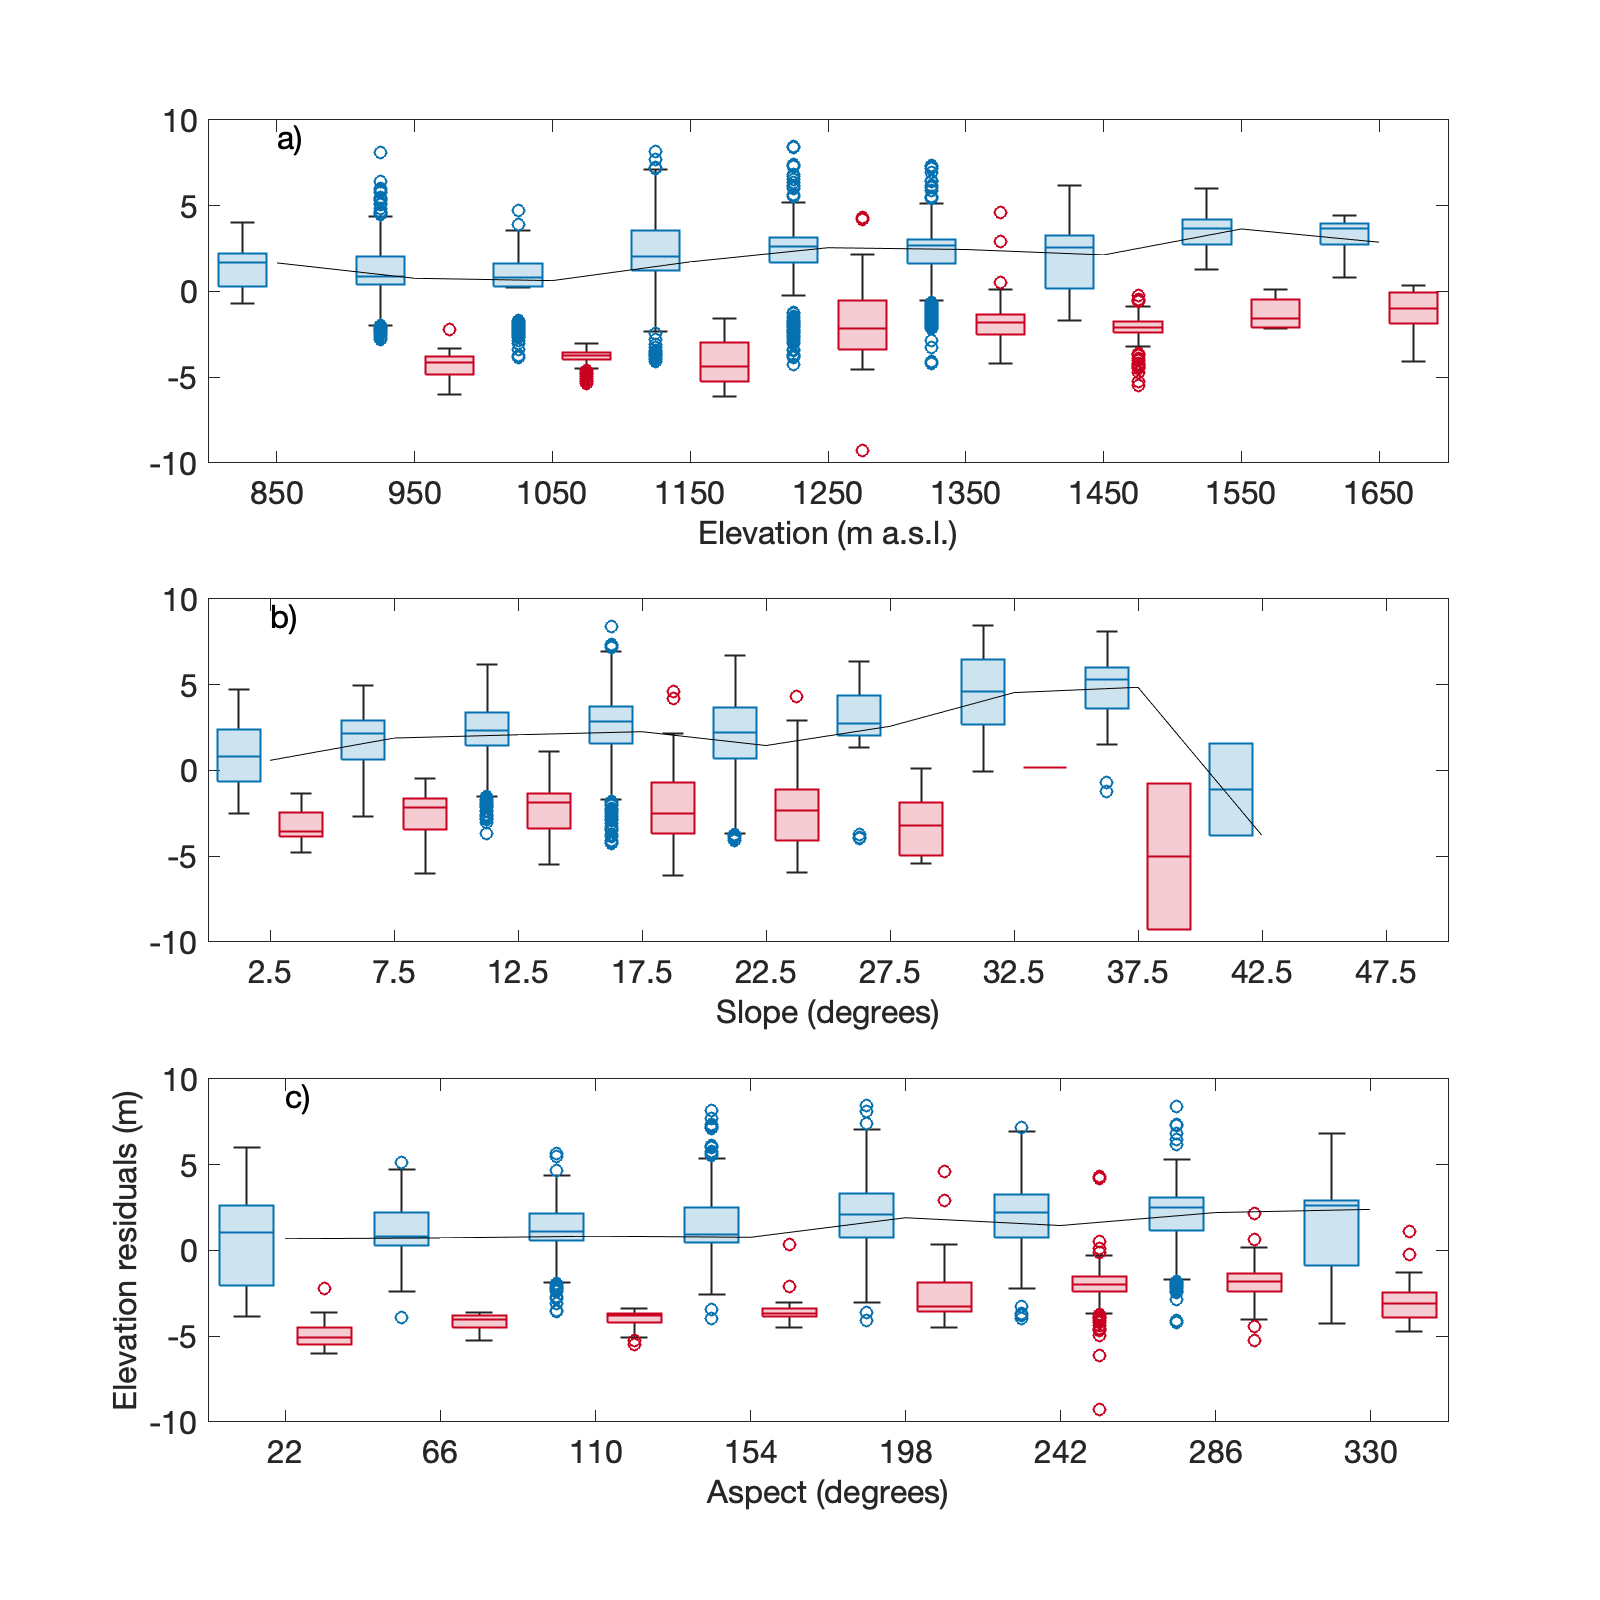

2018.6986 snow-on :


min = 0.7508m, max = 4.3431m, gradient = 0.0040902m/m


2018.6986 snow-off :


min = -4.3941m, max = -1.0189m, gradient = 0.0048544m/m


2019.7205 snow-on :


min = 0.012768m, max = 2.8311m, gradient = -0.0008407m/m


2020.7077 snow-on :


min = -0.9221m, max = 2.913m, gradient = 0.005914m/m


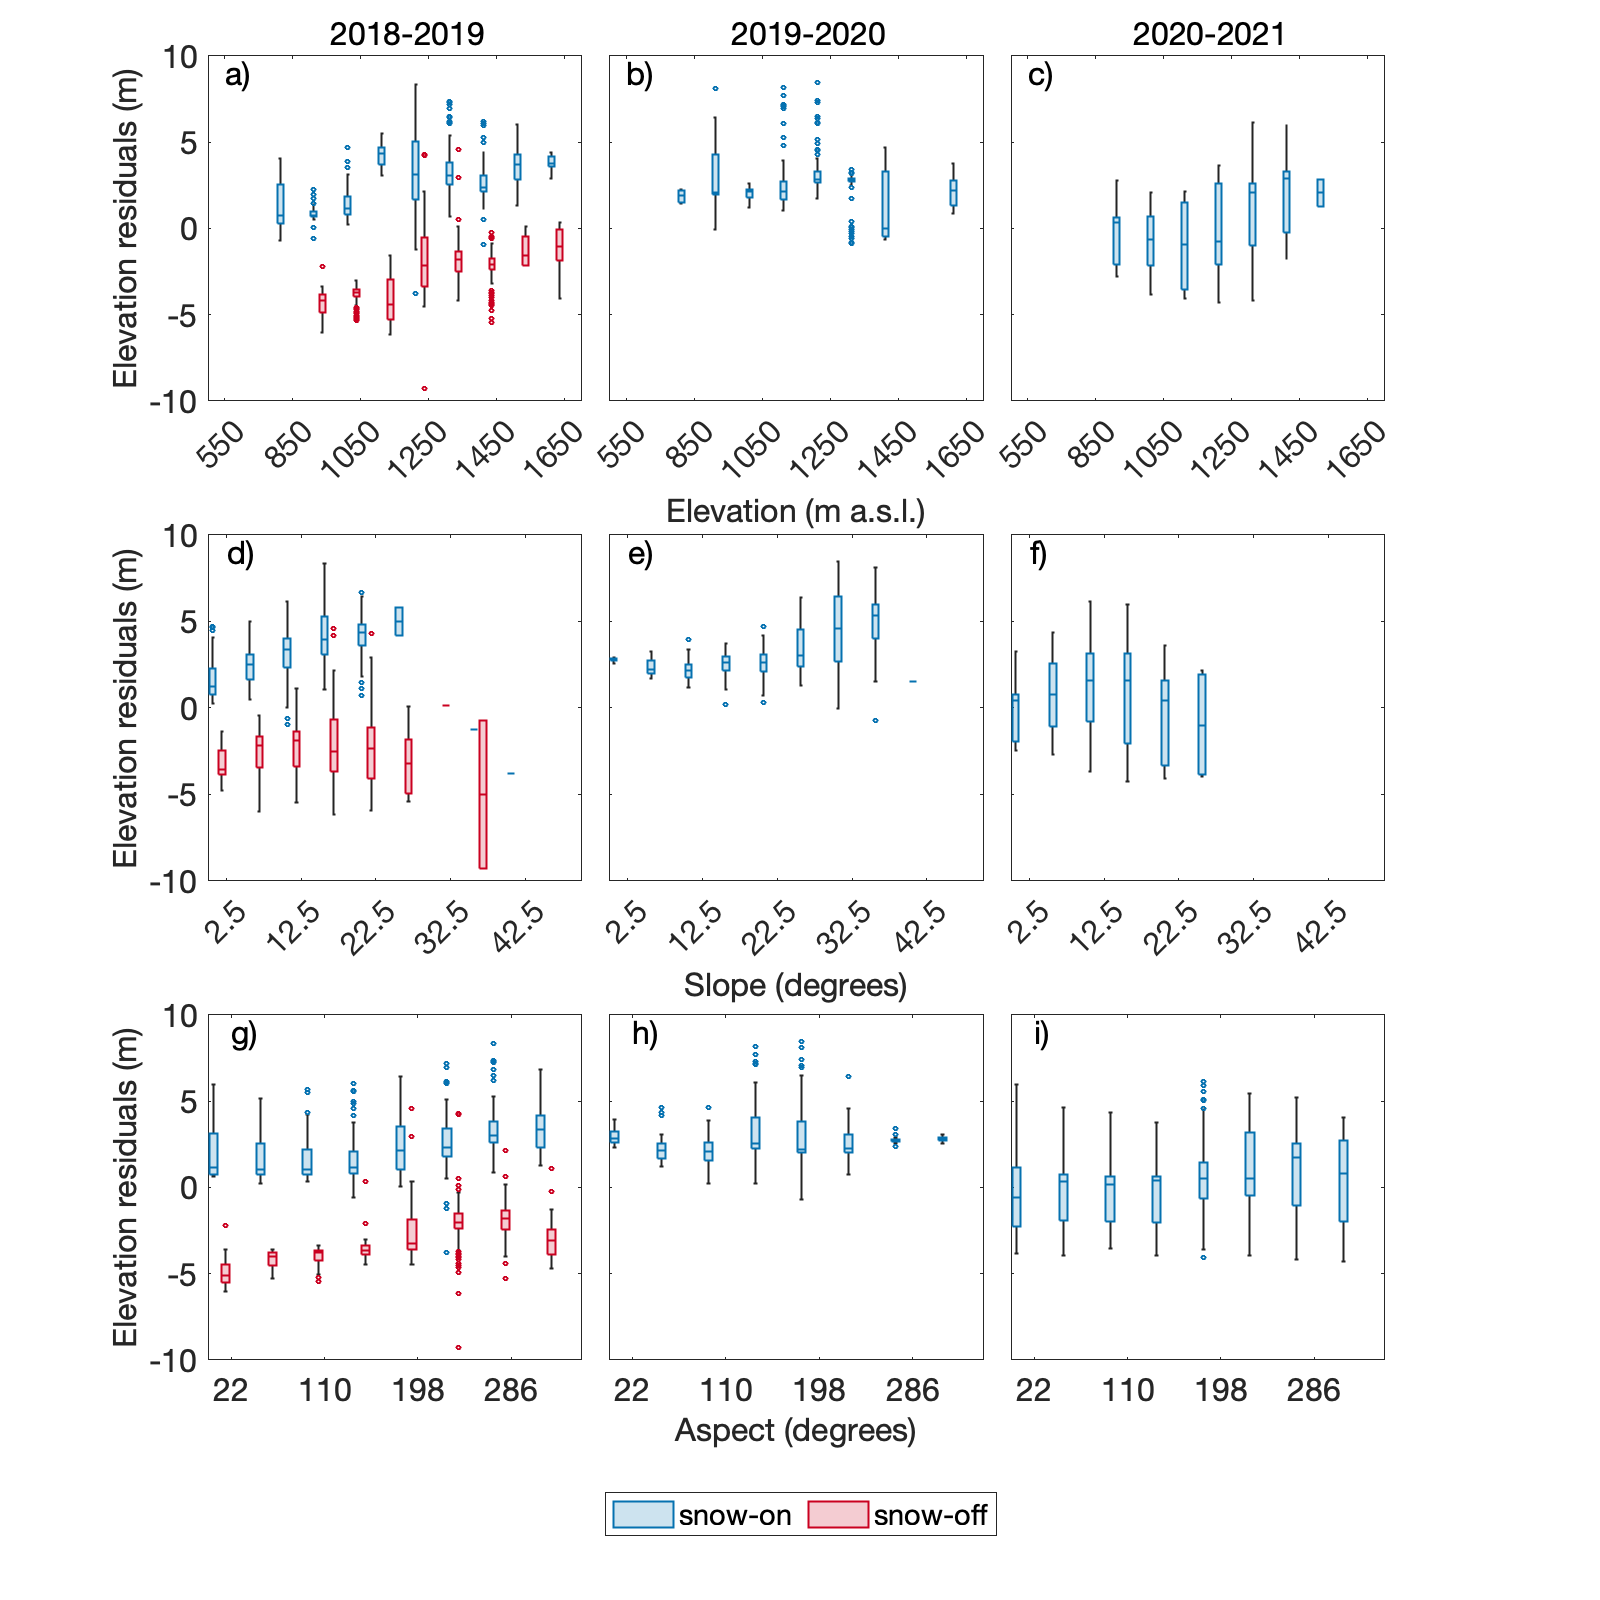

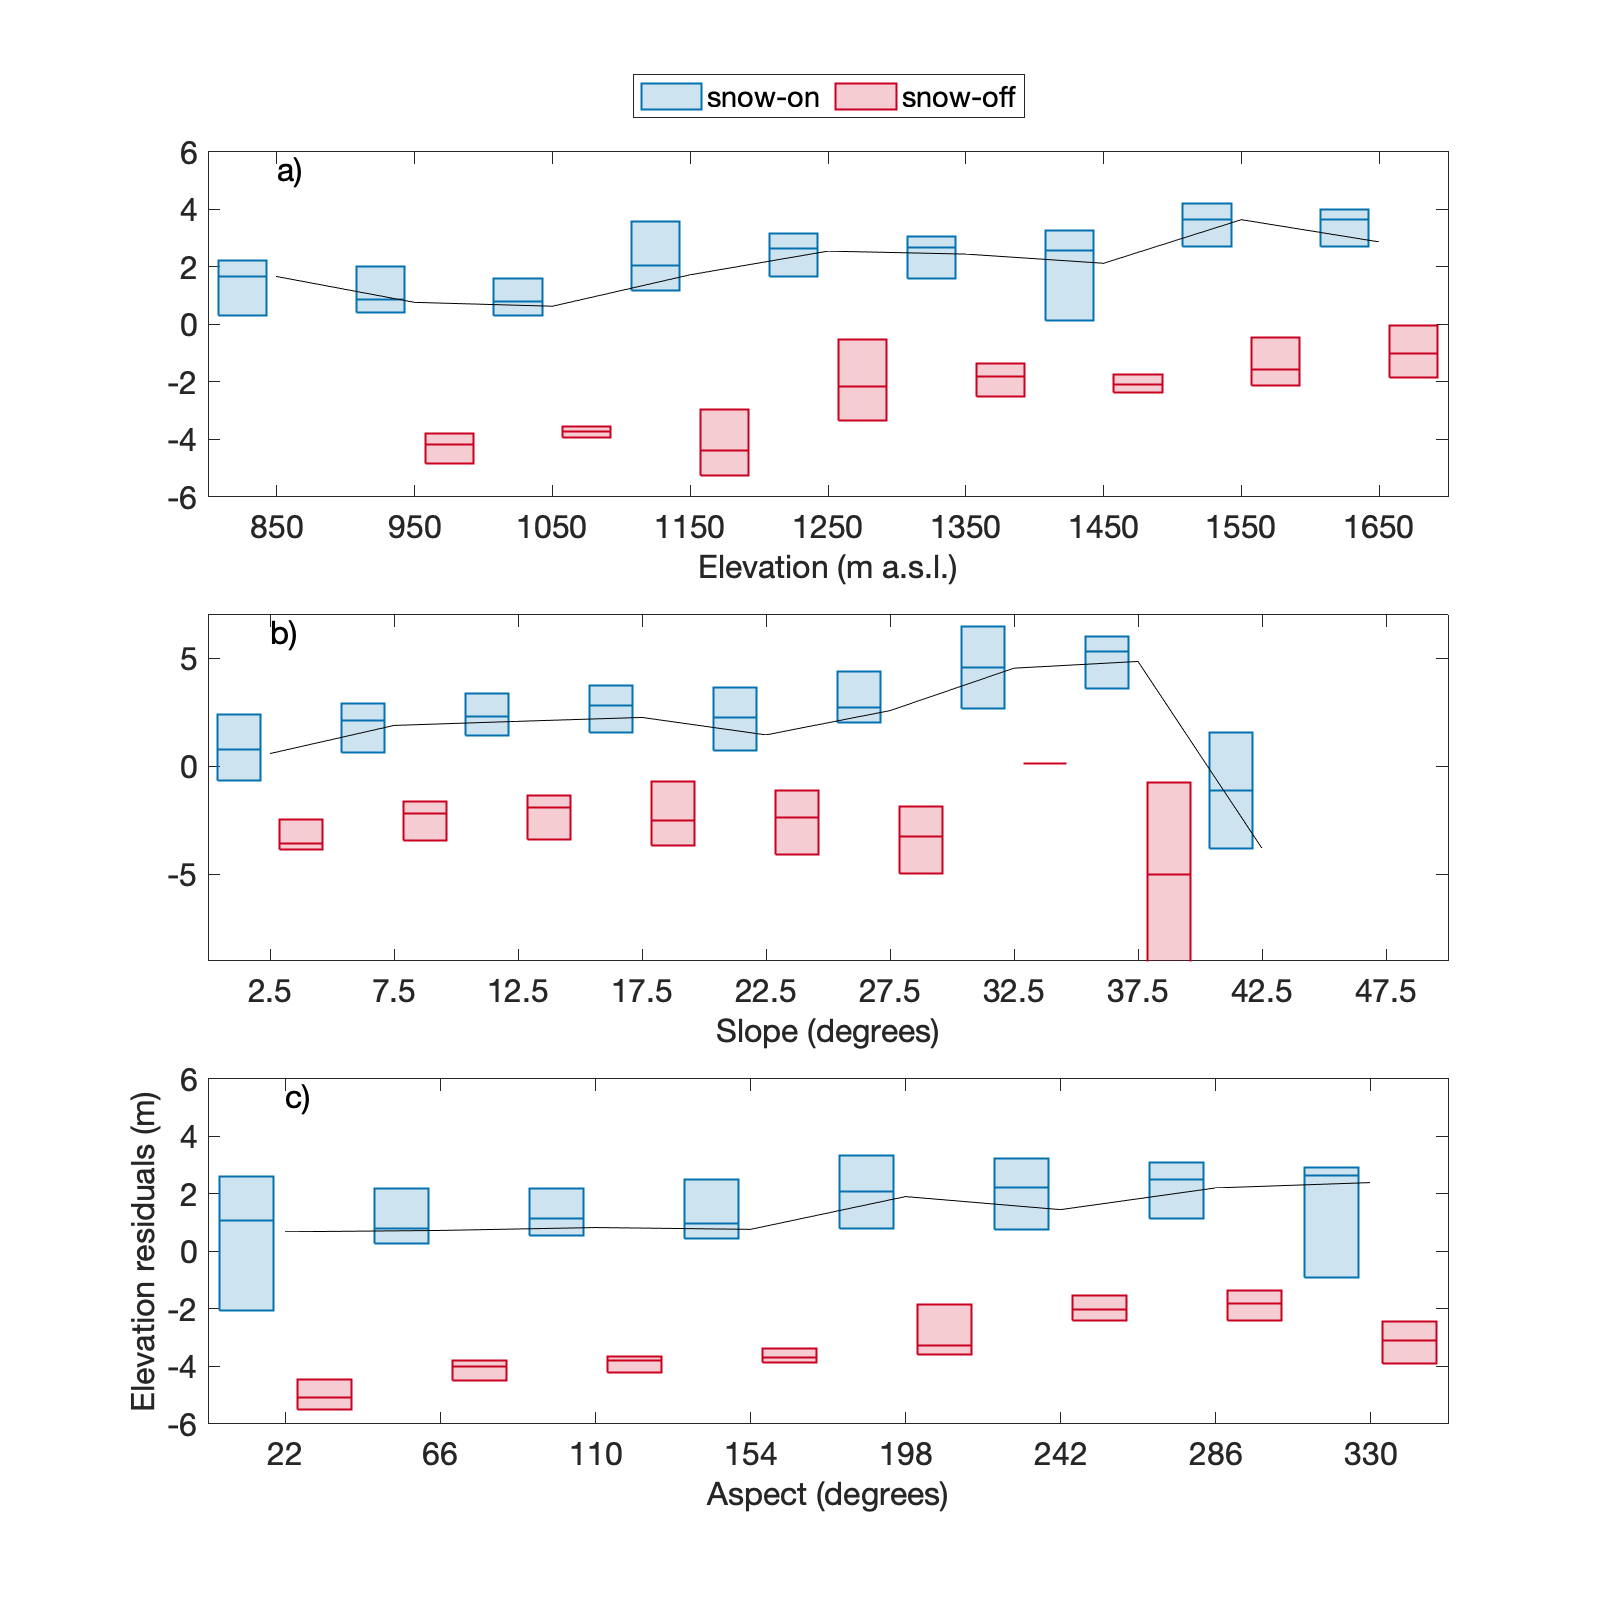

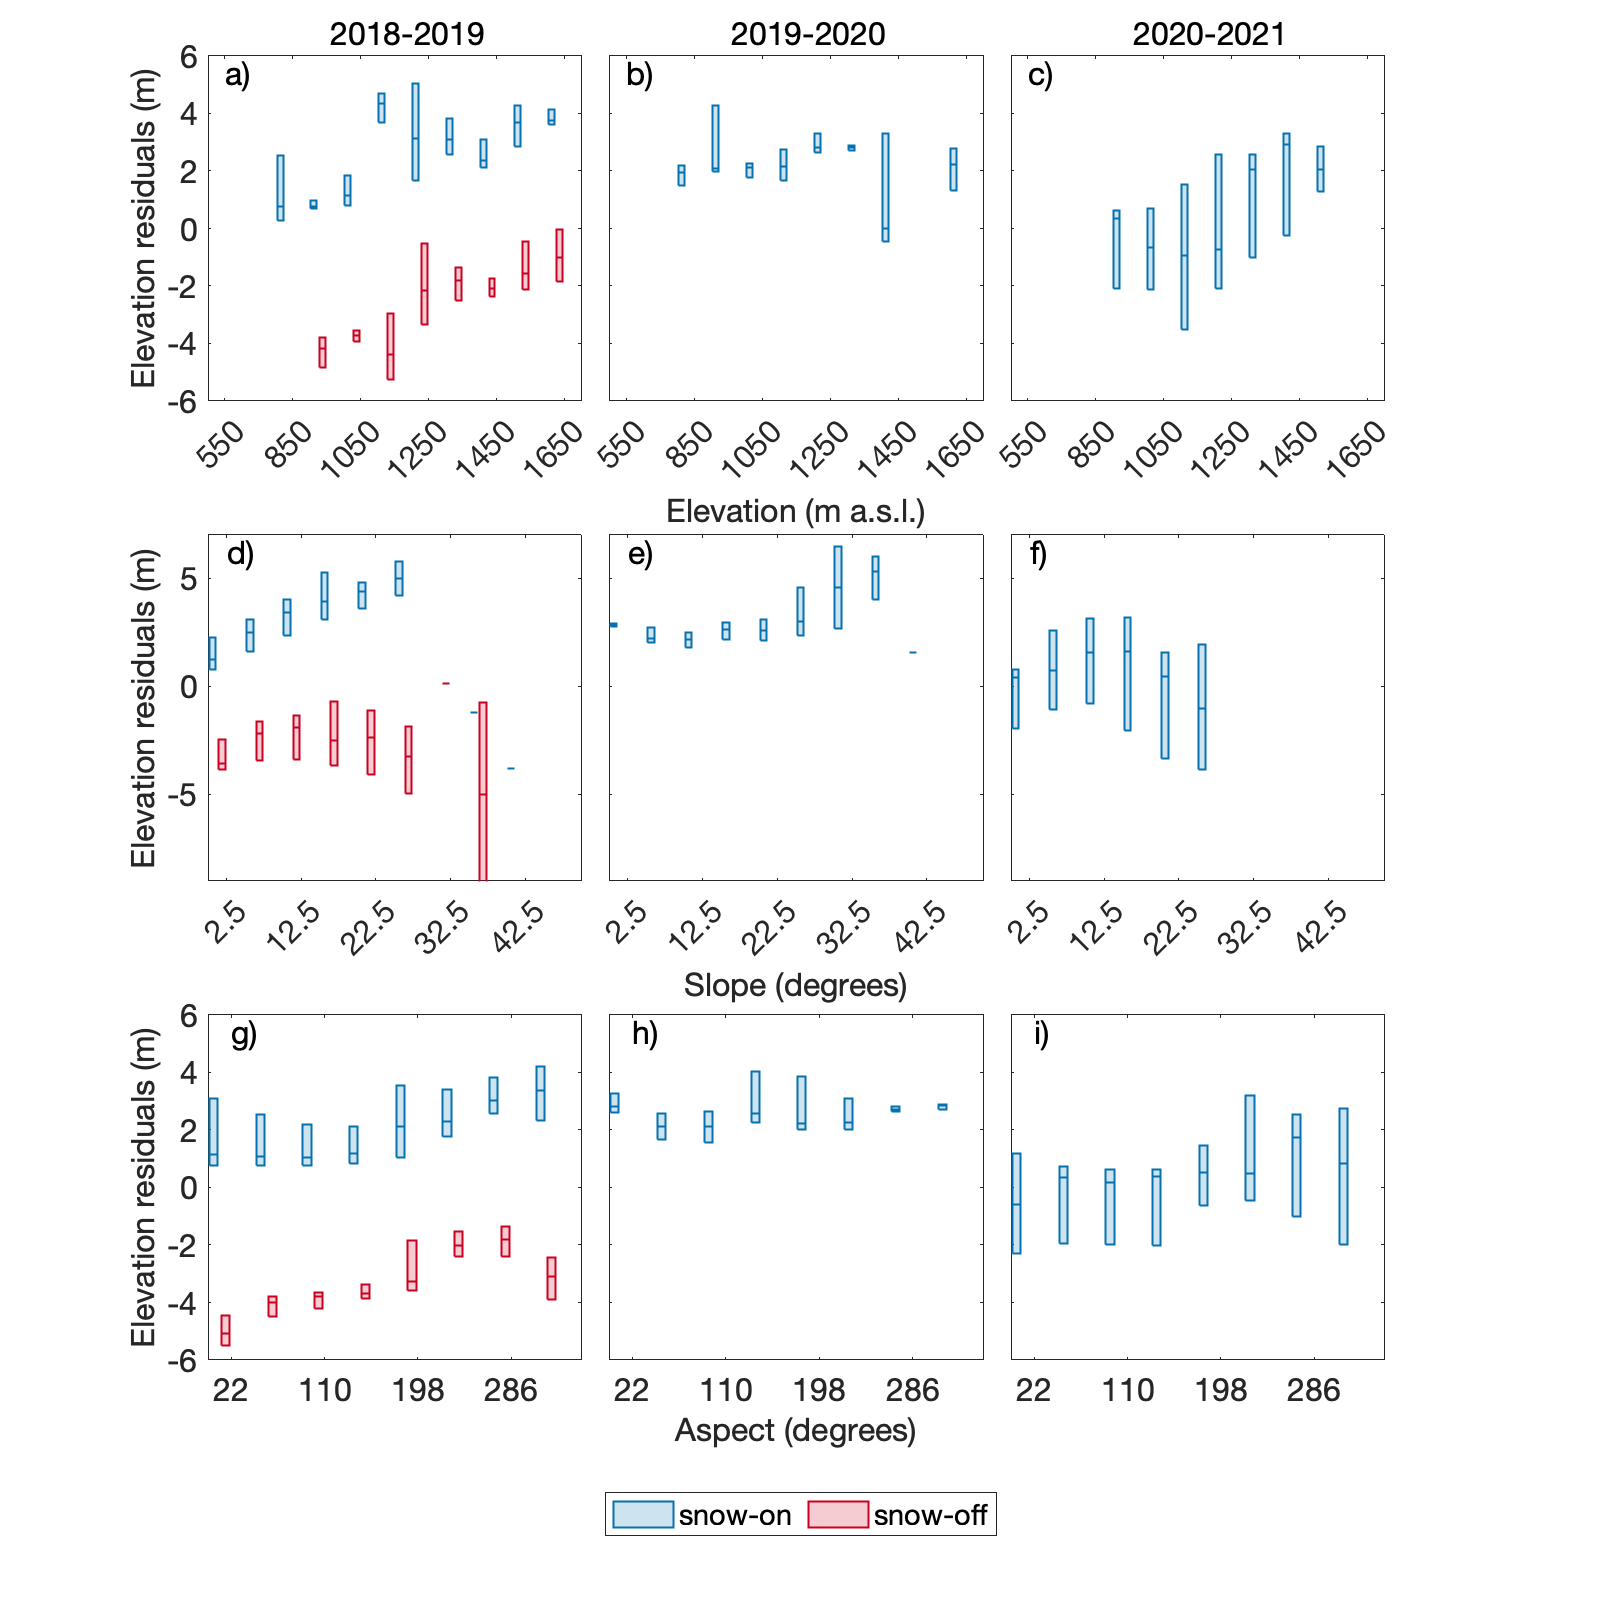

cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%uncomment while loops to automatically determine bin widths for each parameter by identifying the
%bin width that yields >100 observations for the complete dataset
%ELEVATION
h = histogram(Tin.ReferenceElevation(~isnan(Tin.differences)),[floor(min(Tin.ReferenceElevation)/100)*100:100:ceil(max(Tin.ReferenceElevation)/100)*100]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
elev_binwidth = h.BinWidth; elev_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);
%SLOPE
h = histogram(Tin.slope(~isnan(Tin.differences)),[0:5:ceil(max(Tin.slope)/10)*10]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
slope_binwidth = h.BinWidth; slope_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);
%ASPECT
h = histogram(Tin.aspect(~isnan(Tin.differences)),8);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
aspect_binwidth = h.BinWidth; aspect_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);

%create boxplot colormaps
% boxplot_cmap = [wincolor; sprcolor; sumcolor; falcolor];
boxplot_cmap = seas_cmap;

%create boxcharts w/ and w/o whiskers+outliers
for p = 1:2
    
    %specify plot parameters
    if p == 1
        whiskerline = '-'; outliermarker = 'o';
        resid_ylims = [-10 10]; resid_elev_ylims = resid_ylims;
        resid_slope_ylims = resid_ylims; resid_aspect_ylims = resid_ylims;
    else
        whiskerline = 'none'; outliermarker = 'none';
        resid_ylims = [-3.5 2.5]; resid_elev_ylims = [-6 6];
        resid_slope_ylims = [-9 7]; resid_aspect_ylims = [-6 6];
    end
    
    %create boxcharts for each terrain parameter
    figure('position', [0 0 800 800]);
    plot_boxwidth = 0.7; 
    %ELEVATION
    subplot(3,1,1);
    elev_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(Tin.ReferenceElevation>=elev_binedges(j) & Tin.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = Tin.differences(elev_binflag>0); elev_seasflag = Tin.season(elev_binflag>0); elev_binflag(elev_binflag==0) = [];
    elev_seasflag(isnan(resids_elev)) = []; elev_binflag(isnan(resids_elev)) = []; resids_elev(isnan(resids_elev)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag == 1 | elev_seasflag == 2 | elev_seasflag == 4) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(elev_binflag),resids_elev(:,1),'GroupByColor',elev_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_elev(:,1),categorical(elev_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; elevbin = unique(elev_binflag);
    if p == 1
        [~,gof1] = fit(elevbin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly1'); [~,gof2] = fit(elevbin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly2');
        disp(['Residuals vs. elevation R^2: 1st-degree = ',num2str(gof1.rsquare),' & 2nd-degree = ',num2str(gof2.rsquare)]);
        clear gof1 gof2;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_elev_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    if p == 2
        pos = get(gca,'position');
        %     leg = legend('winter','spring','summer','autumn','location','northoutside','Orientation','horizontal');
        leg = legend('snow-on','snow-off','location','northoutside','orientation','horizontal');
        set(gca,'position',[pos(1) pos(2)-0.02 pos(3) pos(4)]);
    end
    xlabel('Elevation (m a.s.l.)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'a)','fontsize',16);
    %SLOPE
    subplot(3,1,2);
    slope_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(Tin.slope>=slope_binedges(j) & Tin.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = Tin.differences(slope_binflag>0); slope_seasflag = Tin.season(slope_binflag>0); slope_binflag(slope_binflag==0) = [];
    slope_seasflag(isnan(resids_slope)) = []; slope_binflag(isnan(resids_slope)) = []; resids_slope(isnan(resids_slope)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag == 1 | slope_seasflag == 2 | slope_seasflag == 4) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(slope_binflag),resids_slope(:,1),'GroupByColor',slope_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_slope(:,1),categorical(slope_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; slopebin = unique(slope_binflag);
    if p == 1
        [~,gof1] = fit(slopebin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly1'); [~,gof2] = fit(slopebin(~isnan(medianresid)),medianresid(~isnan(medianresid)),'poly2');
        disp(['Residuals vs. slope R^2: 1st-degree = ',num2str(gof1.rsquare),' & 2nd-degree = ',num2str(gof2.rsquare)]);
        clear gof1 gof2;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_slope_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    if p == 2
        pos = get(gca,'position');
        set(gca,'position',[pos(1) pos(2)-0.01 pos(3) pos(4)]);
    end
    xlabel('Slope (degrees)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'b)','fontsize',16);
    %ASPECT
    subplot(3,1,3);
    aspect_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(Tin.aspect>=aspect_binedges(j) & Tin.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = Tin.differences(aspect_binflag>0); aspect_seasflag = Tin.season(aspect_binflag>0); aspect_binflag(aspect_binflag==0) = [];
    aspect_seasflag(isnan(resids_aspect)) = []; aspect_binflag(isnan(resids_aspect)) = []; resids_aspect(isnan(resids_aspect)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag == 1 | aspect_seasflag == 2 | aspect_seasflag == 4) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(aspect_binflag),resids_aspect(:,1),'GroupByColor',aspect_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_aspect(:,1),categorical(aspect_binflag),'median');
    plot(medianresid,'-','color','k'); hold off;
    if p == 1
        [~,gof1] = fit(unique(aspect_binflag),medianresid,ft2);
        disp(['Residuals vs. aspect parabolic R^2 = ',num2str(gof1.rsquare)]);
        clear gof1;
    end
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_aspect_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    % leg = legend('winter','spring','summer','autumn','location','southeast');
    xlabel('Aspect (degrees)','fontsize',16); ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'c)','fontsize',16);
    %save figure
    if p == 1
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_boxplots.eps'],'epsc');
    else
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_whiskerless-boxplots.eps'],'epsc');
    end
    clear resids_* *binflag* *seasflag*
    
    
    %divide according to year as well (subplot rows = parameters, columns = years of data)
    figure('Position',[0 0 800 800]);
    subplot_boxwidth = 0.7; subplot_markersize = 2;
    %ELEVATION
    elev_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(Tin.ReferenceElevation>=elev_binedges(j) & Tin.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = Tin.differences(elev_binflag~=0); elev_seasflag = Tin.season(elev_binflag~=0); elev_binflag(elev_binflag==0) = [];
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag == 1 | elev_seasflag == 2 | elev_seasflag == 4) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date(elev_binflag~=0) - Z(j).deciyear;
        resids_elev_annual = resids_elev(ceil(dyear)==1); elev_seasflag_annual = elev_seasflag(ceil(dyear)==1); elev_binflag_annual = elev_binflag(ceil(dyear)==1);
        resids_elev_annual = resids_elev_annual(elev_binflag_annual>0); elev_seasflag_annual = elev_seasflag_annual(elev_binflag_annual>0); elev_binflag_annual(elev_binflag_annual==0) = [];
        elev_seasflag_annual(isnan(resids_elev_annual)) = []; elev_binflag_annual(isnan(resids_elev_annual)) = []; resids_elev_annual(isnan(resids_elev_annual)) = [];
        subplot(3,length(Z),j);
        b = boxchart(categorical([elev_binflag_annual(elev_binflag_annual>0); repmat(unique(elev_binflag(elev_binflag>0)),4,1)]),[resids_elev_annual(elev_binflag_annual>0); NaN(4*length(unique(elev_binflag(elev_binflag>0))),1)],...
            'GroupByColor',[elev_seasflag_annual(elev_binflag_annual>0);ones(length(unique(elev_binflag(elev_binflag>0))),1);2*ones(length(unique(elev_binflag(elev_binflag>0))),1);3*ones(length(unique(elev_binflag(elev_binflag>0))),1);4*ones(length(unique(elev_binflag(elev_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_elev_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Elevation (m a.s.l.)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            %         leg = legend('winter','spring','summer','autumn','location','eastoutside');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        pos = get(gca,'position'); ylims = get(gca,'ylim');
        annotation('textbox',[pos(1)+0.3*pos(3) pos(2)+pos(4)+0.01 0.1 0.02],'string',[num2str(floor(Z(j).deciyear)),'-',num2str(ceil(Z(j).deciyear))],'fontsize',16,'edgecolor','none');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(j),')'],'fontsize',16);
        
         %report statistics for each season
         if p == 1
             %4 seasons
             %         winresids = resids_elev_annual(elev_seasflag_annual==1); winelevs = elev_binflag_annual(elev_seasflag_annual==1);
             %         sprresids = resids_elev_annual(elev_seasflag_annual==2); sprelevs = elev_binflag_annual(elev_seasflag_annual==2);
             %         sumresids = resids_elev_annual(elev_seasflag_annual==3); sumelevs = elev_binflag_annual(elev_seasflag_annual==3);
             %         falresids = resids_elev_annual(elev_seasflag_annual==4); falelevs = elev_binflag_annual(elev_seasflag_annual==4);
             %         elev_bins = unique(elev_binflag_annual);
             %         for k = 1:length(elev_bins)
             %             winmed(k) = nanmedian(winresids(winelevs==elev_bins(k)));
             %             sprmed(k) = nanmedian(sprresids(sprelevs==elev_bins(k)));
             %             summed(k) = nanmedian(sumresids(sumelevs==elev_bins(k)));
             %             falmed(k) = nanmedian(falresids(falelevs==elev_bins(k)));
             %         end
             %         %fit linear polynomials & display data summary
             %         if nansum(winelevs) > 2
             %             [winfit,~] = fit(winelevs,winresids,'poly1');
             %             disp([num2str(Z(j).deciyear),' winter :']);
             %             disp(['min = ',num2str(min(winmed)),'m, max = ',num2str(max(winmed)),'m, gradient = ',num2str(winfit.p1),'m/m']);
             %         end
             %         if nansum(sprelevs) > 2
             %             [sprfit,~] = fit(sprelevs,sprresids,'poly1');
             %             disp([num2str(Z(j).deciyear),' spring :']);
             %             disp(['min = ',num2str(min(sprmed)),'m, max = ',num2str(max(sprmed)),'m, gradient = ',num2str(sprfit.p1),'m/m']);
             %         end
             %         if nansum(sumelevs) > 2
             %             [sumfit,~] = fit(sumelevs,sumresids,'poly1');
             %             disp([num2str(Z(j).deciyear),' summer :']);
             %             disp(['min = ',num2str(min(summed)),'m, max = ',num2str(max(summed)),'m, gradient = ',num2str(sumfit.p1),'m/m']);
             %         end
             %         if nansum(falelevs) > 2
             %             [falfit,~] = fit(falelevs,falresids,'poly1');
             %             disp([num2str(Z(j).deciyear),' autumn :']);
             %             disp(['min = ',num2str(min(falmed)),'m, max = ',num2str(max(falmed)),'m, gradient = ',num2str(falfit.p1),'m/m']);
             %         end
             
             %snow-on and snow-off times of the year
             snowresids = resids_elev_annual(elev_seasflag_annual==1); snowelevs = elev_binflag_annual(elev_seasflag_annual==1);
             dryresids = resids_elev_annual(elev_seasflag_annual==2); dryelevs = elev_binflag_annual(elev_seasflag_annual==2);
             elev_bins = unique(elev_binflag_annual);
             for k = 1:length(elev_bins)
                 snowmed(k) = nanmedian(snowresids(snowelevs==elev_bins(k)));
                 drymed(k) = nanmedian(dryresids(dryelevs==elev_bins(k)));
             end
             %fit linear polynomials & display data summary
             if nansum(snowelevs) > 2
                 [snowfit,~] = fit(snowelevs,snowresids,'poly1');
                 disp([num2str(Z(j).deciyear),' snow-on :']);
                 disp(['min = ',num2str(min(snowmed)),'m, max = ',num2str(max(snowmed)),'m, gradient = ',num2str(snowfit.p1),'m/m']);
             end
             if nansum(dryelevs) > 2
                 [dryfit,~] = fit(dryelevs,dryresids,'poly1');
                 disp([num2str(Z(j).deciyear),' snow-off :']);
                 disp(['min = ',num2str(min(drymed)),'m, max = ',num2str(max(drymed)),'m, gradient = ',num2str(dryfit.p1),'m/m']);
             end
         end
        clear dyear b medianresid *resids *elevs elev_bins *fit *med;
    end
    %SLOPE
    slope_binflag = zeros(size(Tin.slope,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(Tin.slope>=slope_binedges(j) & Tin.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = Tin.differences; slope_seasflag = Tin.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag == 1 | slope_seasflag == 2 | slope_seasflag == 4) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date - Z(j).deciyear;
        resids_slope_annual = resids_slope(ceil(dyear)==1); slope_seasflag_annual = slope_seasflag(ceil(dyear)==1); slope_binflag_annual = slope_binflag(ceil(dyear)==1);
        subplot(3,length(Z),length(Z)+j);
        b = boxchart(categorical([slope_binflag_annual(slope_binflag_annual>0); repmat(unique(slope_binflag(slope_binflag>0)),4,1)]),[resids_slope_annual(slope_binflag_annual>0); NaN(4*length(unique(slope_binflag(slope_binflag>0))),1)],...
            'GroupByColor',[slope_seasflag_annual(slope_binflag_annual>0);ones(length(unique(slope_binflag(slope_binflag>0))),1);2*ones(length(unique(slope_binflag(slope_binflag>0))),1);3*ones(length(unique(slope_binflag(slope_binflag>0))),1);4*ones(length(unique(slope_binflag(slope_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_slope_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Slope (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
%             leg = legend('winter','spring','summer','autumn','location','southoutside','Orientation','horizontal');
            leg = legend('snow-on','snow-off','location','southoutside','orientation','horizontal');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(length(Z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    %ASPECT
    aspect_binflag = zeros(size(Tin.aspect,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(Tin.aspect>=aspect_binedges(j) & Tin.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = Tin.differences; aspect_seasflag = Tin.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag == 1 | aspect_seasflag == 2 | aspect_seasflag == 4) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date - Z(j).deciyear;
        resids_aspect_annual = resids_aspect(ceil(dyear)==1); aspect_seasflag_annual = aspect_seasflag(ceil(dyear)==1); aspect_binflag_annual = aspect_binflag(ceil(dyear)==1);
        subplot(3,length(Z),2*length(Z)+j);
        b = boxchart(categorical([aspect_binflag_annual(aspect_binflag_annual>0); repmat(unique(aspect_binflag(aspect_binflag>0)),4,1)]),[resids_aspect_annual(aspect_binflag_annual>0); NaN(4*length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'GroupByColor',[aspect_seasflag_annual(aspect_binflag_annual>0);ones(length(unique(aspect_binflag(aspect_binflag>0))),1);2*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);3*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);4*ones(length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_aspect_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Aspect (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            %         leg = legend('winter','spring','summer','autumn','location','eastoutside');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(2*length(Z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    legpos = get(leg,'position'); set(leg,'position',[0.5-(0.5*legpos(3)) 0.04 legpos(3) legpos(4)]);
    %save figure
    if p == 1
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_annual-boxplots.eps'],'epsc');
    else
        saveas(gcf,[abbrev,'_ICESat2residuals-vs-terrain_whiskerless-annual-boxplots.eps'],'epsc');
    end
    
end

## Plot Histograms of Elevation Residuals

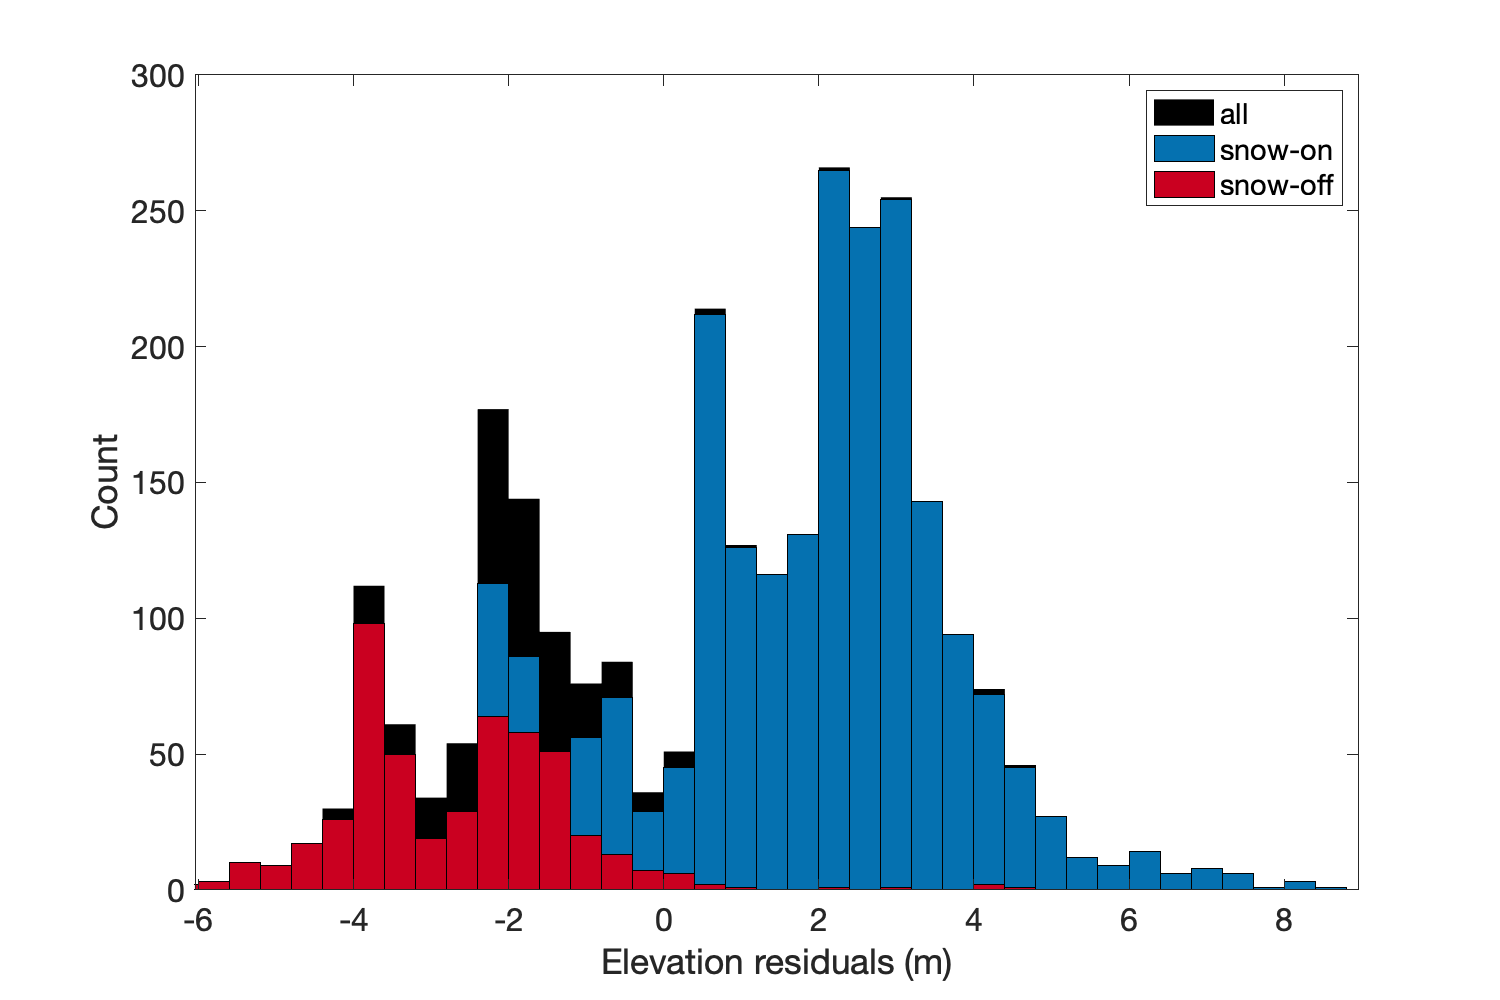

%plot histogram subplots according to year
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%specify the histogram bin width
binwidth = 0.4;

%idetnfiy appropriate histogram limits
max_diff = max([nanmedian(Tin.differences)+3*1.4826*mad(Tin.differences,1),abs(nanmedian(Tin.differences)-3*1.4826*mad(Tin.differences,1))]);

%identify snow-on and snow-off data
acc_diff = Tin.differences(Tin.season == 1 | Tin.season == 2 | Tin.season == 4); acc_date = Tin.date(Tin.season == 1 | Tin.season == 2 | Tin.season == 4); 
abl_diff = Tin.differences(Tin.season == 3); abl_date = Tin.date(Tin.season == 3); 

%plot the histograms
figure; set(gcf,'position',[50 50 750 500]);
raw_ss = abs(Tin.slope); raw_as = abs(Tin.aspect);
Tin.differences(raw_ss>90 | raw_as > 360 | isinf(Tin.differences) | abs(Tin.differences) > 100) = NaN;
h(1) = histogram(Tin.differences); h(1).BinWidth = binwidth; h(1).FaceColor = [0 0 0]; h(1).FaceAlpha = 1;  h(1).EdgeColor = 'none'; hold on;
h(2) = histogram(acc_diff); h(2).BinWidth = binwidth; h(2).FaceColor = seas_cmap(1,:); h(2).FaceAlpha = 1;  h(2).EdgeColor = 'k'; hold on;
h(3) = histogram(abl_diff); h(3).BinWidth = binwidth; h(3).FaceColor = seas_cmap(2,:); h(3).FaceAlpha = 1;  h(3).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16,'xlim',[nanmedian(Tin.differences)-3*1.4826*mad(Tin.differences,1) nanmedian(Tin.differences)+3*1.4826*mad(Tin.differences,1)]); 
leg = legend(h,'all','snow-on','snow-off');
xlabel('Elevation residuals (m)'); ylabel('Count');
saveas(gcf,[abbrev,'_ICESat2residual_histograms.eps'],'epsc');


%histogram subplots according to hydrologic or mass balance year
figure; set(gcf,'position',[50 50 750 1000]);
for i = 1:length(Z)
    subplot(length(Z),1,i);
    h(1) = histogram(acc_diff(ceil(acc_date-Z(i).deciyear)==1),'Normalization','pdf'); h(1).BinWidth = binwidth; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 1;  h(1).EdgeColor = 'k'; hold on;
    h(2) = histogram(abl_diff(ceil(abl_date-Z(i).deciyear)==1),'Normalization','pdf'); h(2).BinWidth = binwidth; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
    %specify limits only if necessary!
    set(gca,'fontsize',16,'xlim',[nanmedian(Tin.differences)-3*1.4826*mad(Tin.differences,1) nanmedian(Tin.differences)+3*1.4826*mad(Tin.differences,1)],...
        'ylim',[0 0.7]); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
    if mod(floor(Z(i).deciyear),4) ~= 0
        if i + 1 <= length(Z)
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last'))),'-',...
                num2str(floor(Z(i+1).deciyear)),'/',num2str(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')),...
                '/',num2str(ceil((Z(i+1).deciyear-floor(Z(i+1).deciyear))*365-cumdays(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')))-1)],...
                'fontsize', 14)
        else
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last'))),'-',...
                num2str(floor(max(T.date))),'/',num2str(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last')),...
                '/',num2str(ceil((max(T.date)-floor(max(T.date)))*365-cumdays(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last'))))],...
                'fontsize', 14)
        end
    else
        if i + 1 <= length(Z)
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*366-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last'))),'-',...
                num2str(floor(Z(i+1).deciyear)),'/',num2str(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')),...
                '/',num2str(ceil((Z(i+1).deciyear-floor(Z(i+1).deciyear))*365-cumdays(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')))-1)],...
                'fontsize', 14)
        else
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*366-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last'))),'-',...
                num2str(floor(max(T.date))),'/',num2str(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last')),...
                '/',num2str(ceil((max(T.date)-floor(max(T.date)))*365-cumdays(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last'))))],...
                'fontsize', 14)
        end
    end
    disp('Data for dates: ')
    alldates = Tin.date(ceil(Tin.date-Z(i).deciyear)==1); alldates = unique(alldates);
    for j = 1:length(alldates)
        if mod(floor(alldates(j)),4) ~= 0
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*365-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')))]);
        else
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*366-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')))]);
        end
    end
    clear alldates;
    
    %statistics on seasonal elevation differences
    disp(['Median +/- MAD elevation residuals relative to: ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),'/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')))])
    fprintf('Snow-on median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1)),mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1));
    fprintf('Snow-off median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1)),mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1));
    
end

Data for dates: 


2019/2/24
2019/2/26
2019/5/28
2019/8/25
2019/8/26


Median +/- MAD elevation residuals relative to: 2018/9/12


Snow-on median +/- MAD elevation residuals= 2.423 +/- 1.129 m

Snow-off median +/- MAD elevation residuals= -2.583 +/- 1.075 m

Data for dates: 


2019/11/24


2020/5/24


Median +/- MAD elevation residuals relative to: 2019/9/20


Snow-on median +/- MAD elevation residuals= 2.640 +/- 0.443 m

Snow-off median +/- MAD elevation residuals= NaN +/- NaN m

Data for dates: 


2020/11/24


2021/2/21
2021/5/22
2021/6/20


Median +/- MAD elevation residuals relative to: 2020/9/15.2923


Snow-on median +/- MAD elevation residuals= 0.546 +/- 1.944 m

Snow-off median +/- MAD elevation residuals= NaN +/- NaN m

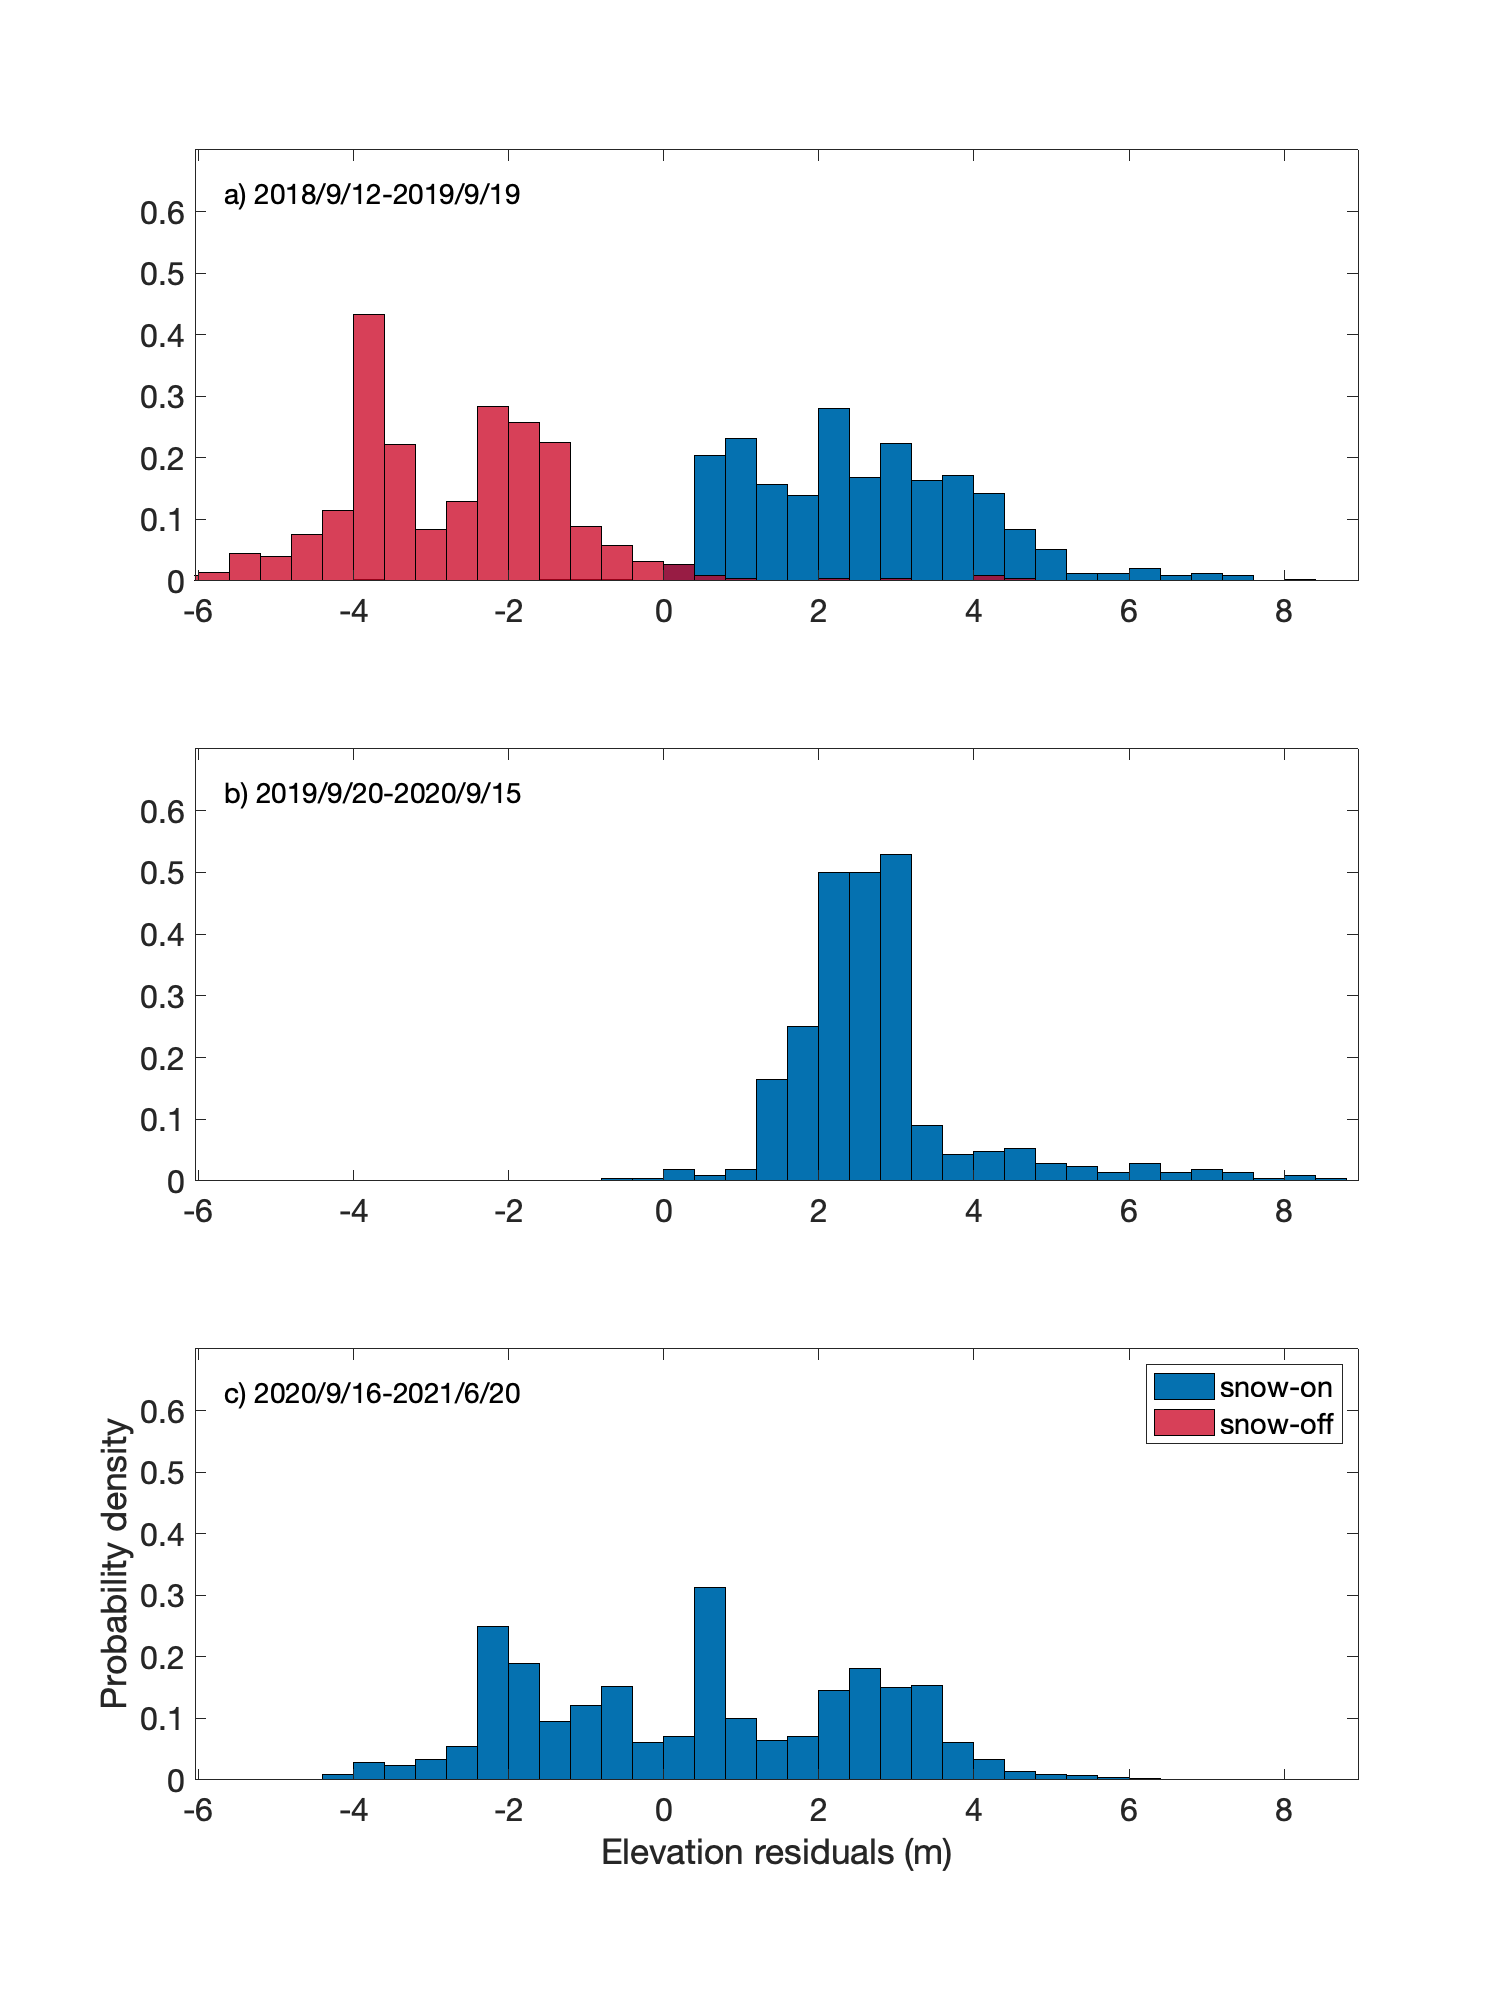

% leg = legend(h,'summer','autumn','winter','spring');
leg = legend(h,'snow-on','snow-off');
xlabel('Elevation residuals (m)'); ylabel('Probability density');
saveas(gcf,[abbrev,'_annual-ICESat2residual_histograms.eps'],'epsc');


%determine whether the on-glacier histograms for each season are
%significantly different from the off-ice summer histogram using the
%two-sample Kolmogorov-Smirnov test (kstest function in Matlab)
disp('Assessing significance of on-glacier elevation residuals wrt coregistration data')

Assessing significance of on-glacier elevation residuals wrt coregistration data


coregdiffs = Tout.differences(Tout.season == coreg_season);
for i = 1:length(Z)
    disp(floor(Z(i).deciyear))
    %winter
    if sum(~isnan(winin.differences(ceil(winin.date-Z(i).deciyear)==1))) > 0
        win_sigtest = kstest2(winin.differences(ceil(winin.date-Z(i).deciyear)==1),coregdiffs);
        if win_sigtest == 1; disp('winter = significantly different'); else; disp('winter = not significantly different'); end
    end
    %spring
    if sum(~isnan(sprin.differences(ceil(sprin.date-Z(i).deciyear)==1))) > 0
        spr_sigtest = kstest2(sprin.differences(ceil(sprin.date-Z(i).deciyear)==1),coregdiffs);
        if spr_sigtest == 1; disp('spring = significantly different'); else; disp('spring = not significantly different'); end
    end
    %summer
    if sum(~isnan(sumin.differences(ceil(sumin.date-Z(i).deciyear)==1))) > 0
        sum_sigtest = kstest2(sumin.differences(ceil(sumin.date-Z(i).deciyear)==1),coregdiffs);
        if sum_sigtest == 1; disp('summer = significantly different'); else; disp('summer = not significantly different'); end
    end
    %fall
    if sum(~isnan(falin.differences(ceil(falin.date-Z(i).deciyear)==1))) > 0
        fal_sigtest = kstest2(falin.differences(ceil(falin.date-Z(i).deciyear)==1),coregdiffs);
        if fal_sigtest == 1; disp('fall = significantly different'); else; disp('fall = not significantly different'); end
    end
end

        2018



winter = significantly different


spring = significantly different


summer = significantly different


        2019



spring = not significantly different


fall = significantly different


        2020



winter = significantly different


spring = significantly different


fall = significantly different


## Plot Histograms of Terrain Parameters

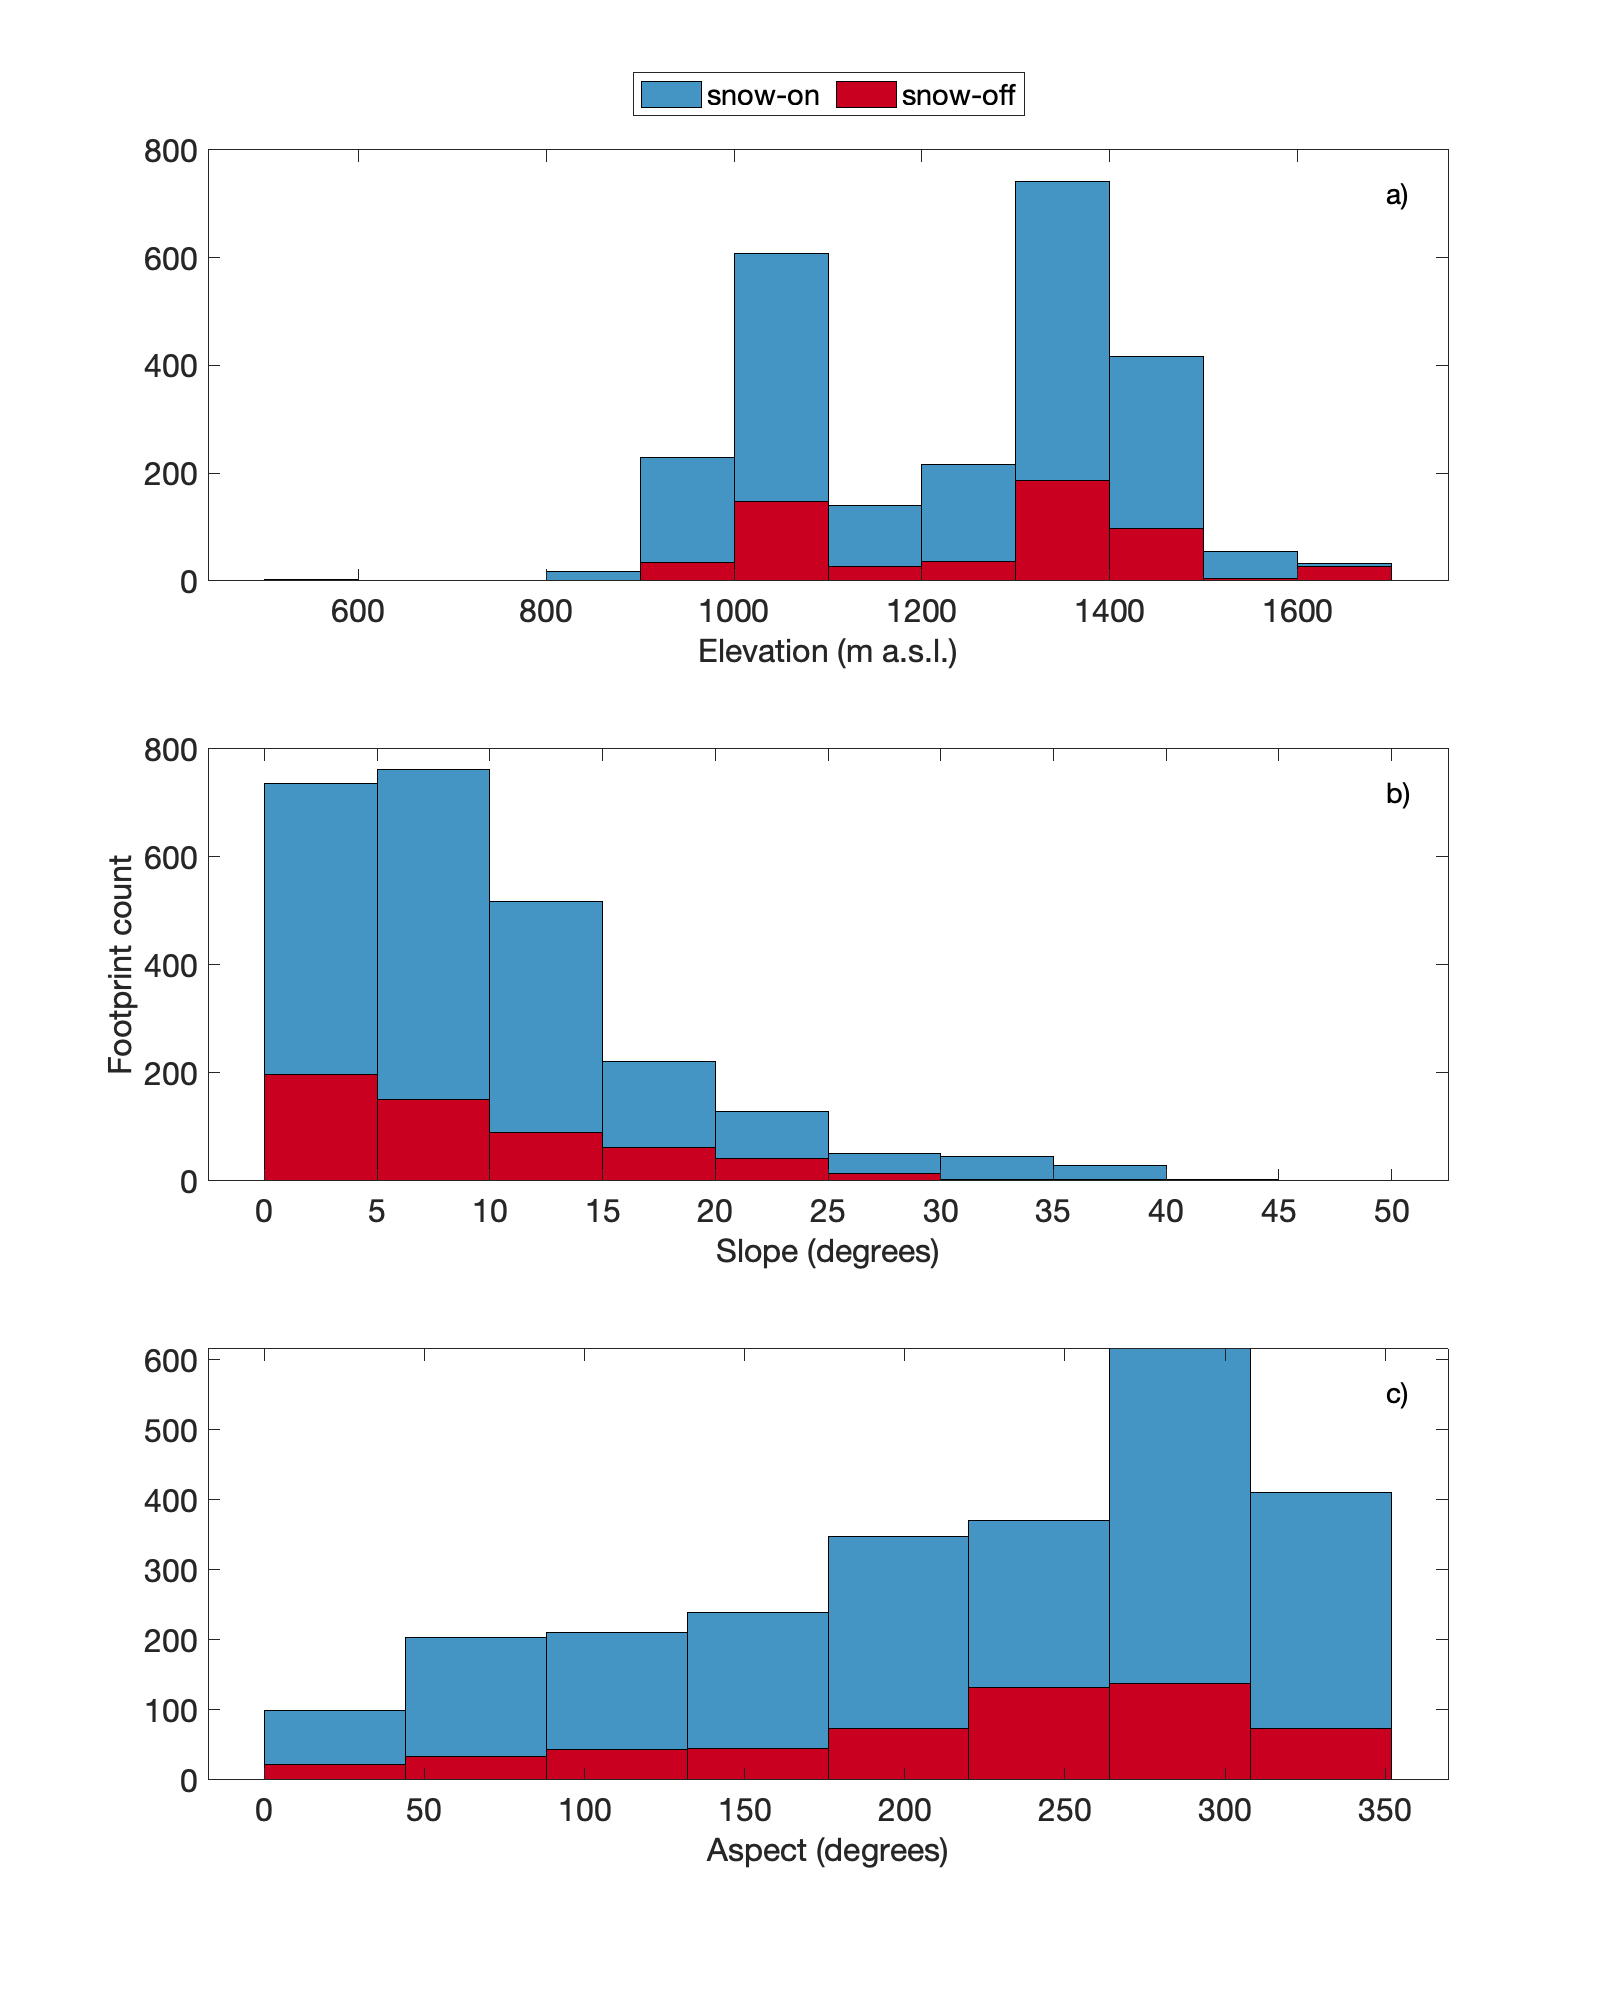

%subplots of seasonal distributions of each terrain parameter to include as
%a supplemental figure to support wonky steep slope & high elevation results (too few observations)

%run previous section to get binwidths
figure; set(gcf,'position',[50 50 800 1000]); clear h;
subplot(3,1,1);
h(1) = histogram(Tin.ReferenceElevation((Tin.season==1 | Tin.season == 2 | Tin.season == 4))); h(1).BinEdges = elev_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.ReferenceElevation((Tin.season==3))); h(2).BinEdges = elev_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 1;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'a) ', 'fontsize', 14);
xlabel('Elevation (m a.s.l.)','fontsize',16); pos = get(gca,'position');
legh = legend(h,'snow-on','snow-off','location','northoutside','orientation','horizontal');
set(gca,'position',pos); clear h pos;
subplot(3,1,2);
h(1) = histogram(Tin.slope((Tin.season==1 | Tin.season == 2 | Tin.season == 4))); h(1).BinEdges = slope_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.slope((Tin.season==3))); h(2).BinEdges = slope_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 1;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'b) ', 'fontsize', 14);
xlabel('Slope (degrees)','fontsize',16);
ylbl = ylabel('Footprint count','fontsize',16); %set(ylbl,'position',[ylbl.Position(1) 200 ylbl.Position(3)]);
subplot(3,1,3);
h(1) = histogram(Tin.aspect((Tin.season==1 | Tin.season == 2 | Tin.season == 4))); h(1).BinEdges = aspect_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.aspect((Tin.season==3))); h(2).BinEdges = aspect_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 1;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'c) ', 'fontsize', 14);
xlabel('Aspect (degrees)','fontsize',16); 


%save the figure
saveas(gcf,[abbrev,'_ICESat2terrain_histograms.eps'],'epsc');

## Fit Trendlines to Elevation Residuals vs. Terrain Parameters

warning off; %suppress occasional warning that iteration limit was reached for robust fit

%referencing note: .differences = residuals, .Elevation_Coregistered = average footprint elevation,
%.slope = average footprint slope, .aspect = average footprint aspect,
%.SlopeRange and .ruggedness = footprint slope range and standard deviation

%ELEVATION
%compute different fits for each "hydrologic" year!
for j = 1:length(Z)
    if height(winin.differences(ceil(winin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fwin_z,fwin_zstats] = fit(winin.ReferenceElevation(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),ft1);
        win_zy=fwin_z.p1 * elev_x+fwin_z.p2; % get y-vectors for line of best fit
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([winin.ReferenceElevation(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fwin_zB2(i,j).p1 = ftout.p1; fwin_zB2(i,j).p2 = ftout.p2;
            fwin_zB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fwin_zB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_elevmodeled(i,:) = feval(ftout,elev_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         win_zmed=nanmedian(residual_elevmodeled,1); win_ziqr=iqr(residual_elevmodeled,1);
        %         clear residual_elevmodeled;
    else
        for i = 1:1000
            fwin_zB2(i,j).p1 = NaN; fwin_zB2(i,j).p2 = NaN; fwin_zB2(i,j).rsquare = NaN; fwin_zB2(i,j).rmse = NaN;
        end
    end
    if height(sprin.differences(ceil(sprin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fspr_z,fspr_zstats] = fit(sprin.ReferenceElevation(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),ft1);
        spr_zy=fspr_z.p1 * elev_x+fspr_z.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([sprin.ReferenceElevation(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fspr_zB2(i,j).p1 = ftout.p1; fspr_zB2(i,j).p2 = ftout.p2;
            fspr_zB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fspr_zB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_elevmodeled(i,:) = feval(ftout,elev_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         spr_zmed=nanmedian(residual_elevmodeled,1); spr_ziqr=iqr(residual_elevmodeled,1);
        %         clear residual_elevmodeled;
    else
        for i = 1:1000
            fspr_zB2(i,j).p1 = NaN; fspr_zB2(i,j).p2 = NaN; fspr_zB2(i,j).rsquare = NaN; fspr_zB2(i,j).rmse = NaN;
        end
    end
    if height(sumin.differences(ceil(sumin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fsum_z,fsum_zstats] = fit(sumin.ReferenceElevation(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),ft1);
        sum_zy=fsum_z.p1 * elev_x+fsum_z.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([sumin.ReferenceElevation(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fsum_zB2(i,j).p1 = ftout.p1; fsum_zB2(i,j).p2 = ftout.p2;
            fsum_zB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fsum_zB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_elevmodeled(i,:) = feval(ftout,elev_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         sum_zmed=nanmedian(residual_elevmodeled,1); sum_ziqr=iqr(residual_elevmodeled,1);
        %         clear residual_elevmodeled;
    else
        for i = 1:1000
            fsum_zB2(i,j).p1 = NaN; fsum_zB2(i,j).p2 = NaN; fsum_zB2(i,j).rsquare = NaN; fsum_zB2(i,j).rmse = NaN;
        end
    end
    if height(falin.differences(ceil(falin.date-Z(j).deciyear)==1)) > 2
        %normal
        [ffal_z,ffal_zstats] = fit(falin.ReferenceElevation(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),ft1);
        fal_zy=ffal_z.p1 * elev_x+ffal_z.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([falin.ReferenceElevation(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            ffal_zB2(i,j).p1 = ftout.p1; ffal_zB2(i,j).p2 = ftout.p2;
            ffal_zB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            ffal_zB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_elevmodeled(i,:) = feval(ftout,elev_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         fal_zmed=nanmedian(residual_elevmodeled,1); fal_ziqr=iqr(residual_elevmodeled,1);
        %         clear residual_elevmodeled;
    else
        for i = 1:1000
            ffal_zB2(i,j).p1 = NaN; ffal_zB2(i,j).p2 = NaN; ffal_zB2(i,j).rsquare = NaN; ffal_zB2(i,j).rmse = NaN;
        end
    end
end

%SLOPE
for j = 1:length(Z)
    if height(winin.differences(ceil(winin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fwin_s,fwin_sstats] = fit(winin.slope(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),ft1);
        win_sy=fwin_s.p1 * slope_x+fwin_s.p2; % get y-vectors for line of best fit
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([winin.slope(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fwin_sB2(i,j).p1 = ftout.p1; fwin_sB2(i,j).p2 = ftout.p2;
            fwin_sB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fwin_sB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_slopemodeled(i,:) = feval(ftout,slope_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         win_smed=nanmedian(residual_slopemodeled,1); win_siqr=iqr(residual_slopemodeled,1);
        %         clear residual_slopemodeled;
    else
        for i = 1:1000
            fwin_sB2(i,j).p1 = NaN; fwin_sB2(i,j).p2 = NaN; fwin_sB2(i,j).rsquare = NaN; fwin_sB2(i,j).rmse = NaN;
        end
    end
    if height(sprin.differences(ceil(sprin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fspr_s,fspr_sstats] = fit(sprin.slope(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),ft1);
        spr_sy=fspr_s.p1 * slope_x+fspr_s.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([sprin.slope(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fspr_sB2(i,j).p1 = ftout.p1; fspr_sB2(i,j).p2 = ftout.p2;
            fspr_sB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fspr_sB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_slopemodeled(i,:) = feval(ftout,slope_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         spr_smed=nanmedian(residual_slopemodeled,1); spr_siqr=iqr(residual_slopemodeled,1);
        %         clear residual_slopemodeled;
    else
        for i = 1:1000
            fspr_sB2(i,j).p1 = NaN; fspr_sB2(i,j).p2 = NaN; fspr_sB2(i,j).rsquare = NaN; fspr_sB2(i,j).rmse = NaN;
        end
    end
    if height(sumin.differences(ceil(sumin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fsum_s,fsum_sstats] = fit(sumin.slope(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),ft1);
        sum_sy=fsum_s.p1 * slope_x+fsum_s.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([sumin.slope(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            fsum_sB2(i,j).p1 = ftout.p1; fsum_sB2(i,j).p2 = ftout.p2;
            fsum_sB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fsum_sB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_slopemodeled(i,:) = feval(ftout,slope_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         sum_smed=nanmedian(residual_slopemodeled,1); sum_siqr=iqr(residual_slopemodeled,1);
        %         clear residual_slopemodeled;
    else
        for i = 1:1000
            fsum_sB2(i,j).p1 = NaN; fsum_sB2(i,j).p2 = NaN; fsum_sB2(i,j).rsquare = NaN; fsum_sB2(i,j).rmse = NaN;
        end
    end
    if height(falin.differences(ceil(falin.date-Z(j).deciyear)==1)) > 2
        %normal
        [ffal_s,ffal_sstats] = fit(falin.slope(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),ft1);
        fal_sy=ffal_s.p1 * slope_x+ffal_s.p2;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([falin.slope(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
            ffal_sB2(i,j).p1 = ftout.p1; ffal_sB2(i,j).p2 = ftout.p2;
            ffal_sB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            ffal_sB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_slopemodeled(i,:) = feval(ftout,slope_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         fal_smed=nanmedian(residual_slopemodeled,1); fal_siqr=iqr(residual_slopemodeled,1);
        %         clear residual_slopemodeled;
    else
        for i = 1:1000
            ffal_sB2(i,j).p1 = NaN; ffal_sB2(i,j).p2 = NaN; ffal_sB2(i,j).rsquare = NaN; ffal_sB2(i,j).rmse = NaN;
        end
    end
end


%ASPECT
for j = 1:length(Z)
    if height(winin.differences(ceil(winin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fwin_a,fwin_astats] = fit(abs(winin.aspect(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.aspect))),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.aspect)),ft2);
        win_ay=fwin_a.a*(aspect_x-180).^2+fwin_a.b;  % get y-vectors for line of best fit
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([abs(winin.aspect(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope))),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
            fwin_aB2(i,j).p1 = ftout.a; fwin_aB2(i,j).p2 = ftout.b; %fwin_aB2(i,j).p1 = ftout.p1;
            fwin_aB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fwin_aB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_aspectmodeled(i,:) = feval(ftout,aspect_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         win_amed=nanmedian(residual_aspectmodeled,1); win_aiqr=iqr(residual_aspectmodeled,1);
        %         clear residual_aspectmodeled;
    else
        for i = 1:1000
            fwin_aB2(i,j).p1 = NaN; fwin_aB2(i,j).p2 = NaN; fwin_aB2(i,j).rsquare = NaN; fwin_aB2(i,j).rmse = NaN;
        end
    end
    if height(sprin.differences(ceil(sprin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fspr_a,fspr_astats] = fit(abs(sprin.aspect(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.aspect))),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.aspect)),ft2);
        spr_ay=fspr_a.a*(aspect_x-180).^2+fspr_a.b;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([abs(sprin.aspect(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope))),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
            fspr_aB2(i,j).p1 = ftout.a; fspr_aB2(i,j).p2 = ftout.b; %fspr_aB2(i,j).p1 = ftout.p1;
            fspr_aB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fspr_aB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_aspectmodeled(i,:) = feval(ftout,aspect_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         spr_amed=nanmedian(residual_aspectmodeled,1); spr_aiqr=iqr(residual_aspectmodeled,1);
        %         clear residual_aspectmodeled;
    else
        for i = 1:1000
            fspr_aB2(i,j).p1 = NaN; fspr_aB2(i,j).p2 = NaN; fspr_aB2(i,j).rsquare = NaN; fspr_aB2(i,j).rmse = NaN;
        end
    end
    if height(sumin.differences(ceil(sumin.date-Z(j).deciyear)==1)) > 2
        %normal
        [fsum_a,fsum_astats] = fit(abs(sumin.aspect(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.aspect))),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.aspect)),ft2);
        sum_ay=fsum_a.a*(aspect_x-180).^2+fsum_a.b;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([abs(sumin.aspect(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope))),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
            fsum_aB2(i,j).p1 = ftout.a; fsum_aB2(i,j).p2 = ftout.b; %fsum_aB2(i,j).p1 = ftout.p1;
            fsum_aB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            fsum_aB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_aspectmodeled(i,:) = feval(ftout,aspect_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         sum_amed=nanmedian(residual_aspectmodeled,1); sum_aiqr=iqr(residual_aspectmodeled,1);
        %         clear residual_aspectmodeled;
    else
        for i = 1:1000
            fsum_aB2(i,j).p1 = NaN; fsum_aB2(i,j).p2 = NaN; fsum_aB2(i,j).rsquare = NaN; fsum_aB2(i,j).rmse = NaN;
        end
    end
    if height(falin.differences(ceil(falin.date-Z(j).deciyear)==1)) > 2
        %normal
        [ffal_a,ffal_astats] = fit(abs(falin.aspect(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.aspect))),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.aspect)),ft2);
        fal_ay=ffal_a.a*(aspect_x-180).^2+ffal_a.b;
        %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
        for i = 1:1000
            [trainset,testset]=getTrainTest([abs(falin.aspect(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope))),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope))],0.9);
            
            [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft2,opts);
            ffal_aB2(i,j).p1 = ftout.a; ffal_aB2(i,j).p2 = ftout.b; %ffal_aB2(i,j).p1 = ftout.p1;
            ffal_aB2(i,j).rsquare = ftstats.rsquare;
            testset_modeled = feval(ftout,testset(:,1));
            ffal_aB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
            %             residual_aspectmodeled(i,:) = feval(ftout,aspect_x);
            clear trainset testset ftout ftstats testset_modeled;
        end
        %         fal_amed=nanmedian(residual_aspectmodeled,1); fal_aiqr=iqr(residual_aspectmodeled,1);
        %         clear residual_aspectmodeled;
    else
        for i = 1:1000
            ffal_aB2(i,j).p1 = NaN; ffal_aB2(i,j).p2 = NaN; ffal_aB2(i,j).rsquare = NaN; ffal_aB2(i,j).rmse = NaN;
        end
    end
end


% %RUGGEDNESS
% for j = 1:length(Z)
%     if height(winin.differences(ceil(winin.date-Z(j).deciyear)==1)) > 2
%         %normal
%         [fwin_r,fwin_rstats] = fit(winin.ruggedness(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.ruggedness)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.ruggedness)),ft1);
%         win_ry=fwin_r.p1 * rough_x+fwin_r.p2; % get y-vectors for line of best fit
%         %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
%         for i = 1:1000
%             [trainset,testset]=getTrainTest([winin.ruggedness(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope)),winin.differences(ceil(winin.date-Z(j).deciyear)==1 & ~isnan(winin.differences) & ~isnan(winin.slope))],0.9);
%             
%             [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%             fwin_rB2(i,j).p1 = ftout.p1; fwin_rB2(i,j).p2 = ftout.p2;
%             fwin_rB2(i,j).rsquare = ftstats.rsquare;
%             testset_modeled = feval(ftout,testset(:,1));
%             fwin_rB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%             %             residual_roughmodeled(i,:) = feval(ftout,rough_x);
%             clear trainset testset ftout ftstats testset_modeled;
%         end
%         %         win_rmed=nanmedian(residual_roughmodeled,1); win_riqr=iqr(residual_roughmodeled,1);
%         %         clear residual_roughmodeled;
%     else
%         for i = 1:1000
%             fwin_rB2(i,j).p1 = NaN; fwin_rB2(i,j).p2 = NaN; fwin_rB2(i,j).rsquare = NaN; fwin_rB2(i,j).rmse = NaN;
%         end
%     end
%     if height(sprin.differences(ceil(sprin.date-Z(j).deciyear)==1)) > 2
%         %normal
%         [fspr_r,fspr_rstats] = fit(sprin.ruggedness(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.ruggedness)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.ruggedness)),ft1);
%         spr_ry=fspr_r.p1 * rough_x+fspr_r.p2;
%         %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
%         for i = 1:1000
%             [trainset,testset]=getTrainTest([sprin.ruggedness(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope)),sprin.differences(ceil(sprin.date-Z(j).deciyear)==1 & ~isnan(sprin.differences) & ~isnan(sprin.slope))],0.9);
%             
%             [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%             fspr_rB2(i,j).p1 = ftout.p1; fspr_rB2(i,j).p2 = ftout.p2;
%             fspr_rB2(i,j).rsquare = ftstats.rsquare;
%             testset_modeled = feval(ftout,testset(:,1));
%             fspr_rB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%             %             residual_roughmodeled(i,:) = feval(ftout,rough_x);
%             clear trainset testset ftout ftstats testset_modeled;
%         end
%         %         spr_rmed=nanmedian(residual_roughmodeled,1); spr_riqr=iqr(residual_roughmodeled,1);
%         %         clear residual_roughmodeled;
%     else
%         for i = 1:1000
%             fspr_rB2(i,j).p1 = NaN; fspr_rB2(i,j).p2 = NaN; fspr_rB2(i,j).rsquare = NaN; fspr_rB2(i,j).rmse = NaN;
%         end
%     end
%     if height(sumin.differences(ceil(sumin.date-Z(j).deciyear)==1)) > 2
%         %normal
%         [fsum_r,fsum_rstats] = fit(sumin.ruggedness(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.ruggedness)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.ruggedness)),ft1);
%         sum_ry=fsum_r.p1 * rough_x+fsum_r.p2;
%         %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
%         for i = 1:1000
%             [trainset,testset]=getTrainTest([sumin.ruggedness(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope)),sumin.differences(ceil(sumin.date-Z(j).deciyear)==1 & ~isnan(sumin.differences) & ~isnan(sumin.slope))],0.9);
%             
%             [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%             fsum_rB2(i,j).p1 = ftout.p1; fsum_rB2(i,j).p2 = ftout.p2;
%             fsum_rB2(i,j).rsquare = ftstats.rsquare;
%             testset_modeled = feval(ftout,testset(:,1));
%             fsum_rB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%             %             residual_roughmodeled(i,:) = feval(ftout,rough_x);
%             clear trainset testset ftout ftstats testset_modeled;
%         end
%         %         sum_rmed=nanmedian(residual_roughmodeled,1); sum_riqr=iqr(residual_roughmodeled,1);
%         %         clear residual_roughmodeled;
%     else
%         for i = 1:1000
%             fsum_rB2(i,j).p1 = NaN; fsum_rB2(i,j).p2 = NaN; fsum_rB2(i,j).rsquare = NaN; fsum_rB2(i,j).rmse = NaN;
%         end
%     end
%     if height(falin.differences(ceil(falin.date-Z(j).deciyear)==1)) > 2
%         %normal
%         [ffal_r,ffal_rstats] = fit(falin.ruggedness(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.ruggedness)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.ruggedness)),ft1);
%         fal_ry=ffal_r.p1 * rough_x+ffal_r.p2;
%         %bisquare (iteratively fit w/ 90% of data to get confidence bounds)
%         for i = 1:1000
%             [trainset,testset]=getTrainTest([falin.ruggedness(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope)),falin.differences(ceil(falin.date-Z(j).deciyear)==1 & ~isnan(falin.differences) & ~isnan(falin.slope))],0.9);
%             
%             [ftout,ftstats] = fit(trainset(:,1),trainset(:,2),ft1,opts);
%             ffal_rB2(i,j).p1 = ftout.p1; ffal_rB2(i,j).p2 = ftout.p2;
%             ffal_rB2(i,j).rsquare = ftstats.rsquare;
%             testset_modeled = feval(ftout,testset(:,1));
%             ffal_rB2(i,j).rmse = sqrt(sum((testset_modeled-testset(:,2)).^2)./length(testset_modeled));
%             %             residual_roughmodeled(i,:) = feval(ftout,rough_x);
%             clear trainset testset ftout ftstats testset_modeled;
%         end
%         %         fal_rmed=nanmedian(residual_roughmodeled,1); fal_riqr=iqr(residual_roughmodeled,1);
%         %         clear residual_roughmodeled;
%     else
%         for i = 1:1000
%             ffal_rB2(i,j).p1 = NaN; ffal_rB2(i,j).p2 = NaN; ffal_rB2(i,j).rsquare = NaN; ffal_rB2(i,j).rmse = NaN;
%         end
%     end
% end


%save fit outputs
disp('Fit curves')
save([abbrev,'-ICESat2_elevation-residuals_v_elevation_fits.mat'],'fwin_zB2','fspr_zB2','fsum_zB2','ffal_zB2');
save([abbrev,'-ICESat2_elevation-residuals_v_slope_fits.mat'],'fwin_sB2','fspr_sB2','fsum_sB2','ffal_sB2');
save([abbrev,'-ICESat2_elevation-residuals_v_aspect_fits.mat'],'fwin_aB2','fspr_aB2','fsum_aB2','ffal_aB2');
% save([abbrev,'-ICESat2_elevation-residuals_v_ruggedness_fits.mat'],'fwin_rB2','fspr_rB2','fsum_rB2','ffal_rB2');

clear *med *iqr;

## Create Scatterplots of Elevation Residuals vs Terrain Parameters

%extract trendlines & uncertainties
close all;

%reload data
load_elevfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_elevation_fits.mat']; eval(load_elevfits);
load_slopefits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_slope_fits.mat']; eval(load_slopefits);
load_aspectfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_aspect_fits.mat']; eval(load_aspectfits);
% load_roughfits = ['load ',abbrev,'-ICESat2_elevation-residuals_v_ruggedness_fits.mat']; eval(load_roughfits);

%set up the symbol key for the annual trendline plots
line_type = {'-','--','-.'}; for j = 1:length(Z); Zyrs(j) = floor(Z(j).deciyear); end

%compile median trendlines
for j = 1:length(Z)
    for i = 1:1000
        %WINTER
        win_zslope(i,j) = fwin_zB2(i,j).p1; win_zintercept(i,j) = fwin_zB2(i,j).p2;
        win_sslope(i,j) = fwin_sB2(i,j).p1; win_sintercept(i,j) = fwin_sB2(i,j).p2;
        win_aslope(i,j) = fwin_aB2(i,j).p1; win_aintercept(i,j) = fwin_aB2(i,j).p2;
%         win_rslope(i,j) = fwin_rB2(i,j).p1; win_rintercept(i,j) = fwin_rB2(i,j).p2;
        %SPRING
        spr_zslope(i,j) = fspr_zB2(i,j).p1; spr_zintercept(i,j) = fspr_zB2(i,j).p2;
        spr_sslope(i,j) = fspr_sB2(i,j).p1; spr_sintercept(i,j) = fspr_sB2(i,j).p2;
        spr_aslope(i,j) = fspr_aB2(i,j).p1; spr_aintercept(i,j) = fspr_aB2(i,j).p2;
%         spr_rslope(i,j) = fspr_rB2(i,j).p1; spr_rintercept(i,j) = fspr_rB2(i,j).p2;
        %SUMMER
        sum_zslope(i,j) = fsum_zB2(i,j).p1; sum_zintercept(i,j) = fsum_zB2(i,j).p2;
        sum_sslope(i,j) = fsum_sB2(i,j).p1; sum_sintercept(i,j) = fsum_sB2(i,j).p2;
        sum_aslope(i,j) = fsum_aB2(i,j).p1; sum_aintercept(i,j) = fsum_aB2(i,j).p2;
%         sum_rslope(i,j) = fsum_rB2(i,j).p1; sum_rintercept(i,j) = fsum_rB2(i,j).p2;
        %FALL
        fal_zslope(i,j) = ffal_zB2(i,j).p1; fal_zintercept(i,j) = ffal_zB2(i,j).p2;
        fal_sslope(i,j) = ffal_sB2(i,j).p1; fal_sintercept(i,j) = ffal_sB2(i,j).p2;
        fal_aslope(i,j) = ffal_aB2(i,j).p1; fal_aintercept(i,j) = ffal_aB2(i,j).p2;
%         fal_rslope(i,j) = ffal_rB2(i,j).p1; fal_rintercept(i,j) = ffal_rB2(i,j).p2;
    end
end
%create modeled fit lines
for j = 1:length(Z)
    %WINTER
    win_zB2y(j,:)=nanmedian(win_zslope(:,j).*elev_x+win_zintercept(:,j));
    win_sB2y(j,:)=nanmedian(win_sslope(:,j).*slope_x+win_sintercept(:,j));
    win_aB2y(j,:)=nanmedian(win_aslope(:,j).*(aspect_x-180).^2+win_aintercept(:,j));
%     win_rB2y(j,:)=nanmedian(win_rslope(:,j).*rough_x+win_rintercept(:,j));
    win_zB2iqr(j,:)=iqr(win_zslope(:,j).*elev_x+win_zintercept(:,j));
    win_sB2iqr(j,:)=iqr(win_sslope(:,j).*slope_x+win_sintercept(:,j));
    win_aB2iqr(j,:)=iqr(win_aslope(:,j).*(aspect_x-180).^2+win_aintercept(:,j));
%     win_rB2iqr(j,:)=iqr(win_rslope(:,j).*rough_x+win_rintercept(:,j));
    %SPRING
    spr_zB2y(j,:)=nanmedian(spr_zslope(:,j).*elev_x+spr_zintercept(:,j));
    spr_sB2y(j,:)=nanmedian(spr_sslope(:,j).*slope_x+spr_sintercept(:,j));
    spr_aB2y(j,:)=nanmedian(spr_aslope(:,j).*(aspect_x-180).^2+spr_aintercept(:,j));
%     spr_rB2y(j,:)=nanmedian(spr_rslope(:,j).*rough_x+spr_rintercept(:,j));
    spr_zB2iqr(j,:)=iqr(spr_zslope(:,j).*elev_x+spr_zintercept(:,j));
    spr_sB2iqr(j,:)=iqr(spr_sslope(:,j).*slope_x+spr_sintercept(:,j));
    spr_aB2iqr(j,:)=iqr(spr_aslope(:,j).*(aspect_x-180).^2+spr_aintercept(:,j));
%     spr_rB2iqr(j,:)=iqr(spr_rslope(:,j).*rough_x+spr_rintercept(:,j));
    %SUMMER
    sum_zB2y(j,:)=nanmedian(sum_zslope(:,j).*elev_x+sum_zintercept(:,j));
    sum_sB2y(j,:)=nanmedian(sum_sslope(:,j).*slope_x+sum_sintercept(:,j));
    sum_aB2y(j,:)=nanmedian(sum_aslope(:,j).*(aspect_x-180).^2+sum_aintercept(:,j));
%     sum_rB2y(j,:)=nanmedian(sum_rslope(:,j).*rough_x+sum_rintercept(:,j));
    sum_zB2iqr(j,:)=iqr(sum_zslope(:,j).*elev_x+sum_zintercept(:,j));
    sum_sB2iqr(j,:)=iqr(sum_sslope(:,j).*slope_x+sum_sintercept(:,j));
    sum_aB2iqr(j,:)=iqr(sum_aslope(:,j).*(aspect_x-180).^2+sum_aintercept(:,j));
%     sum_rB2iqr(j,:)=iqr(sum_rslope(:,j).*rough_x+sum_rintercept(:,j));
    %FALL
    fal_zB2y(j,:)=nanmedian(fal_zslope(:,j).*elev_x+fal_zintercept(:,j));
    fal_sB2y(j,:)=nanmedian(fal_sslope(:,j).*slope_x+fal_sintercept(:,j));
    fal_aB2y(j,:)=nanmedian(fal_aslope(:,j).*(aspect_x-180).^2+fal_aintercept(:,j));
%     fal_rB2y(j,:)=nanmedian(fal_rslope(:,j).*rough_x+fal_rintercept(:,j));
    fal_zB2iqr(j,:)=iqr(fal_zslope(:,j).*elev_x+fal_zintercept(:,j));
    fal_sB2iqr(j,:)=iqr(fal_sslope(:,j).*slope_x+fal_sintercept(:,j));
    fal_aB2iqr(j,:)=iqr(fal_aslope(:,j).*(aspect_x-180).^2+fal_aintercept(:,j));
%     fal_rB2iqr(j,:)=iqr(fal_rslope(:,j).*rough_x+fal_rintercept(:,j));
end

%set plot bounds
max_diff = max([nanmedian(T.differences)+3*1.4826*mad(T.differences,1),abs(nanmedian(T.differences)-3*1.4826*mad(T.differences,1))]);

%extract RMSEs for each bisquare fit
for j = 1:length(Z)
    for i = 1:1000
        win_zRMSE(i,j) = fwin_zB2(i,j).rmse; spr_zRMSE(i,j) = fspr_zB2(i,j).rmse; sum_zRMSE(i,j) = fsum_zB2(i,j).rmse; fal_zRMSE(i,j) = ffal_zB2(i,j).rmse;
        win_sRMSE(i,j) = fwin_sB2(i,j).rmse; spr_sRMSE(i,j) = fspr_sB2(i,j).rmse; sum_sRMSE(i,j) = fsum_sB2(i,j).rmse; fal_sRMSE(i,j) = ffal_sB2(i,j).rmse;
        win_aRMSE(i,j) = fwin_aB2(i,j).rmse; spr_aRMSE(i,j) = fspr_aB2(i,j).rmse; sum_aRMSE(i,j) = fsum_aB2(i,j).rmse; fal_aRMSE(i,j) = ffal_aB2(i,j).rmse;
%         win_rRMSE(i,j) = fwin_rB2(i,j).rmse; spr_rRMSE(i,j) = fspr_rB2(i,j).rmse; sum_rRMSE(i,j) = fsum_rB2(i,j).rmse; fal_rRMSE(i,j) = ffal_rB2(i,j).rmse;
    end
end

%ELEVATION
disp('Residuals vs Elevation:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winout.ReferenceElevation, winout.differences, 12, 's', 'markeredgecolor',wincolor,'markerfacecolor','none'); hold on;
scatter(winin.ReferenceElevation, winin.differences, 18, 's','markeredgecolor',wincolor/1.5,'markerfacecolor','none','linewidth',1.5); hold on
if height(winin)>2
    for j = 1:length(Z)
        plot(elev_x, win_zB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim'); ylbl= ylabel('Elevation residual (m)');
disp('Winter')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(win_zintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(win_zslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(win_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_zRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(win_zslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(win_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_zRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprout.ReferenceElevation, sprout.differences, 12, 's', 'markeredgecolor',sprcolor,'markerfacecolor', 'none'); hold on;
scatter(sprin.ReferenceElevation, sprin.differences, 18, 's','markeredgecolor',(sprcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sprin)>2
    for j = 1:length(Z)
        plot(elev_x, spr_zB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(spr_zintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(spr_zslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(spr_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_zRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(spr_zslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(spr_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_zRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumout.ReferenceElevation, sumout.differences, 12, 's', 'markeredgecolor',sumcolor,'markerfacecolor', 'none'); hold on;
scatter(sumin.ReferenceElevation, sumin.differences, 18, 's','markeredgecolor',(sumcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sumin)>2
    for j = 1:length(Z)
        plot(elev_x, sum_zB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim'); ylbl= ylabel('Elevation residual (m)');
disp('Summer')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(sum_zintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(sum_zslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(sum_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_zRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(sum_zslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(sum_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_zRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
%insert lots of plot placeholders in legend to organize it appropriately
sp(1) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none'); hold on;
sp(2) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none'); hold on;
sp(3) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none'); hold on;
sp(4) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','k','markerfacecolor','none'); hold on;
scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor',falcolor,'markerfacecolor','none'); hold on;
sp(5) = scatter(falin.ReferenceElevation, falin.differences, 18, 's','markeredgecolor','k','markerfacecolor','none','linewidth',1.5); hold on
scatter(falin.ReferenceElevation, falin.differences, 18, 's','markeredgecolor',(falcolor)/1.5,'markerfacecolor','none','linewidth',1.5); hold on
sp(6) = scatter(falin.ReferenceElevation, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(7) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none');
sp(8) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none');
sp(9) = scatter(falout.ReferenceElevation, falout.differences, 12, 's', 'markeredgecolor','none','markerfacecolor','none');
if height(falin)>2
    for j = 1:length(Z)
        sp(9+j) = plot(elev_x, fal_zB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
leg = legend(sp,' ',' ',' ','off-ice', 'on-ice',' ',' ',' ',' ',num2str(Zyrs(1)),num2str(Zyrs(2)),num2str(Zyrs(3)),'NumColumns',4,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(fal_zintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(fal_zslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(fal_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_zRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(fal_zslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(fal_zintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_zRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.33 0.5 0.4 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winin)>2
    for j = 1:length(Z)
        fill([elev_x fliplr(elev_x)],[win_zB2y(j,:)+win_zB2iqr(j,:) fliplr(win_zB2y(j,:)-win_zB2iqr(j,:))]-min(win_zB2y(j,:)),wincolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(elev_x, win_zB2y(j,:)-min(win_zB2y(j,:)), [char(line_type(j))],'color',wincolor,'linewidth', 2);
    end
end
if height(sprin)>2
    for j = 1:length(Z)
        fill([elev_x fliplr(elev_x)],[spr_zB2y(j,:)+spr_zB2iqr(j,:) fliplr(spr_zB2y(j,:)-spr_zB2iqr(j,:))]-min(spr_zB2y(j,:)),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(elev_x, spr_zB2y(j,:)-min(spr_zB2y(j,:)), [char(line_type(j))],'color',sprcolor,'linewidth', 2);
    end
end
if height(sumin)>2
    for j = 1:length(Z)
        fill([elev_x fliplr(elev_x)],[sum_zB2y(j,:)+sum_zB2iqr(j,:) fliplr(sum_zB2y(j,:)-sum_zB2iqr(j,:))]-min(sum_zB2y(j,:)),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(elev_x, sum_zB2y(j,:)-min(sum_zB2y(j,:)), [char(line_type(j))],'color',sumcolor,'linewidth', 2);
    end
end
if height(falin)>2
    for j = 1:length(Z)
        fill([elev_x fliplr(elev_x)],[fal_zB2y(j,:)+fal_zB2iqr(j,:) fliplr(fal_zB2y(j,:)-fal_zB2iqr(j,:))]-min(fal_zB2y(j,:)),falcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(elev_x, fal_zB2y(j,:)-min(fal_zB2y(j,:)), [char(line_type(j))],'color',falcolor,'linewidth', 2);
    end
end
ylim([min([min(win_zB2y(~isnan(win_zB2y))-win_zB2iqr(~isnan(win_zB2y)))-min(win_zB2y(~isnan(win_zB2y))) min(spr_zB2y(~isnan(spr_zB2y))-spr_zB2iqr(~isnan(spr_zB2y)))-min(spr_zB2y(~isnan(spr_zB2y))) min(sum_zB2y(~isnan(sum_zB2y))-sum_zB2iqr(~isnan(sum_zB2y)))-min(sum_zB2y(~isnan(sum_zB2y))) min(fal_zB2y(~isnan(fal_zB2y))-fal_zB2iqr(~isnan(fal_zB2y)))-min(fal_zB2y(~isnan(fal_zB2y)))]),...
    max([max(win_zB2y(~isnan(win_zB2y))+win_zB2iqr(~isnan(win_zB2y)))-min(win_zB2y(~isnan(win_zB2y))) max(spr_zB2y(~isnan(spr_zB2y))+spr_zB2iqr(~isnan(spr_zB2y)))-min(spr_zB2y(~isnan(spr_zB2y))) max(sum_zB2y(~isnan(sum_zB2y))+sum_zB2iqr(~isnan(sum_zB2y)))-min(sum_zB2y(~isnan(sum_zB2y))) max(fal_zB2y(~isnan(fal_zB2y))+fal_zB2iqr(~isnan(fal_zB2y)))-min(fal_zB2y(~isnan(fal_zB2y)))])]);
xlim([min(elev_x) max(elev_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) all trends ','fontsize',16);
xlbl = xlabel('Elevation (m a.s.l.)'); ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(elev_x)-0.05*(max(elev_x)-min(elev_x)) 0.5*max(ylims) -1]);
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
%add categories and dividers to the legend
annotation('textbox','position',[0.35 0.53 0.1 0.05],'string','residuals','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('textbox','position',[0.55 0.515 0.1 0.05],'string','trends','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('line',[0.54 0.54],[0.5 0.6],'linewidth',1.5);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-elevation.eps'],'epsc');


%SLOPE
disp('Residuals vs Slope:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winout.slope, winout.differences, 12, 's', 'markeredgecolor', wincolor,'markerfacecolor','none'); hold on;
scatter(winin.slope, winin.differences, 18, 's','markeredgecolor',wincolor/1.5,'markerfacecolor','none','linewidth',1.5); hold on
if height(winin)>2
    for j = 1:length(Z)
        plot(slope_x, win_sB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim'); ylbl= ylabel('Elevation residual (m)');
disp('Winter')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(win_sintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(win_sslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(win_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_sRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(win_sslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(win_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_sRMSE),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprout.slope, sprout.differences, 12, 's', 'markeredgecolor', sprcolor,'markerfacecolor','none'); hold on;
scatter(sprin.slope, sprin.differences, 18, 's','markeredgecolor',(sprcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sprin)>2
    for j = 1:length(Z)
        plot(slope_x, spr_sB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(spr_sintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(spr_sslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(spr_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_sRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(spr_sslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(spr_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_sRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumout.slope, sumout.differences, 12, 's', 'markeredgecolor', sumcolor,'markerfacecolor', 'none'); hold on;
scatter(sumin.slope, sumin.differences, 18, 's','markeredgecolor',(sumcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sumin)>2
    for j = 1:length(Z)
        plot(slope_x, sum_sB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer  ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(sum_sintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(sum_sslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(sum_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_sRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(sum_sslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(sum_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_sRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on'); ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
%insert lots of plot placeholders in legend to organize it appropriately
sp(1) = scatter(falout.slope, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(2) = scatter(falout.slope, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(3) = scatter(falout.slope, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(4) = scatter(falout.slope, falout.differences, 12, 's', 'markeredgecolor', 'k','markerfacecolor','none'); hold on;
scatter(falout.slope, falout.differences, 12, 's', 'markeredgecolor', falcolor,'markerfacecolor','none'); hold on;
sp(5) = scatter(falin.slope, falin.differences, 18, 's','markeredgecolor','k','markerfacecolor','none','linewidth',1.5); hold on
scatter(falin.slope, falin.differences, 18, 's','markeredgecolor',(falcolor)/1.5,'markerfacecolor','none','linewidth',1.5); hold on
sp(6) = scatter(falin.slope, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(7) = scatter(falin.slope, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(8) = scatter(falin.slope, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(9) = scatter(falin.slope, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
if height(falin)>2
    for j = 1:length(Z)
        sp(9+j) = plot(slope_x, fal_sB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
leg = legend(sp,' ',' ',' ','off-ice', 'on-ice',' ',' ',' ',' ',num2str(Zyrs(1)),num2str(Zyrs(2)),num2str(Zyrs(3)),'NumColumns',4,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(fal_sintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(fal_sslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(fal_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_sRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(fal_sslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(fal_sintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_sRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winin)>2
    for j = 1:length(Z)
        fill([slope_x fliplr(slope_x)],[win_sB2y(j,:)+win_sB2iqr(j,:) fliplr(win_sB2y(j,:)-win_sB2iqr(j,:))]-min(win_sB2y(j,:)),wincolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(slope_x, win_sB2y(j,:)-min(win_sB2y(j,:)), [char(line_type(j))],'color',wincolor,'linewidth', 2);
    end
end
if height(sprin)>2
    for j = 1:length(Z)
        fill([slope_x fliplr(slope_x)],[spr_sB2y(j,:)+spr_sB2iqr(j,:) fliplr(spr_sB2y(j,:)-spr_sB2iqr(j,:))]-min(spr_sB2y(j,:)),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(slope_x, spr_sB2y(j,:)-min(spr_sB2y(j,:)), [char(line_type(j))],'color',sprcolor,'linewidth', 2);
    end
end
if height(sumin)>2
    for j = 1:length(Z)
        fill([slope_x fliplr(slope_x)],[sum_sB2y(j,:)+sum_sB2iqr(j,:) fliplr(sum_sB2y(j,:)-sum_sB2iqr(j,:))]-min(sum_sB2y(j,:)),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(slope_x, sum_sB2y(j,:)-min(sum_sB2y(j,:)), [char(line_type(j))],'color',sumcolor,'linewidth', 2);
    end
end
if height(falin)>2
    for j = 1:length(Z)
        fill([slope_x fliplr(slope_x)],[fal_sB2y(j,:)+fal_sB2iqr(j,:) fliplr(fal_sB2y(j,:)-fal_sB2iqr(j,:))]-min(fal_sB2y(j,:)),falcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(slope_x, fal_sB2y(j,:)-min(fal_sB2y(j,:)), [char(line_type(j))],'color',falcolor,'linewidth', 2);
    end
end
ylim([min([min(win_sB2y(~isnan(win_sB2y))-win_sB2iqr(~isnan(win_sB2y)))-min(win_sB2y(~isnan(win_sB2y))) min(spr_sB2y(~isnan(spr_sB2y))-spr_sB2iqr(~isnan(spr_sB2y)))-min(spr_sB2y(~isnan(spr_sB2y))) min(sum_sB2y(~isnan(sum_sB2y))-sum_sB2iqr(~isnan(sum_sB2y)))-min(sum_sB2y(~isnan(sum_sB2y))) min(fal_sB2y(~isnan(fal_sB2y))-fal_sB2iqr(~isnan(fal_sB2y)))-min(fal_sB2y(~isnan(fal_sB2y)))]),...
    max([max(win_sB2y(~isnan(win_sB2y))+win_sB2iqr(~isnan(win_sB2y)))-min(win_sB2y(~isnan(win_sB2y))) max(spr_sB2y(~isnan(spr_sB2y))+spr_sB2iqr(~isnan(spr_sB2y)))-min(spr_sB2y(~isnan(spr_sB2y))) max(sum_sB2y(~isnan(sum_sB2y))+sum_sB2iqr(~isnan(sum_sB2y)))-min(sum_sB2y(~isnan(sum_sB2y))) max(fal_sB2y(~isnan(fal_sB2y))+fal_sB2iqr(~isnan(fal_sB2y)))-min(fal_sB2y(~isnan(fal_sB2y)))])]);
xlim([min(slope_x) max(slope_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) all trends ','fontsize',16);
xlbl = xlabel('Slope (degrees)'); ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(slope_x)-0.05*(max(slope_x)-min(slope_x)) 0.5*max(ylims) -1]);
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
%add categories and dividers to the legend
annotation('textbox','position',[0.35 0.53 0.1 0.05],'string','residuals','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('textbox','position',[0.55 0.515 0.1 0.05],'string','trends','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('line',[0.54 0.54],[0.5 0.6],'linewidth',1.5);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-slope.eps'],'epsc');


%ASPECT
disp('Residuals vs Aspect:')
figure('position', [0 0 800 800])
sub1 = subplot(3,2,1); pos1 = get(gca,'position');
scatter(winout.aspect, winout.differences, 12, 's', 'markeredgecolor', wincolor,'markerfacecolor','none'); hold on;
scatter(winin.aspect, winin.differences, 18, 's','markeredgecolor',wincolor/1.5,'markerfacecolor','none','linewidth',1.5); hold on
if height(winin)>2
    for j = 1:length(Z)
        plot(aspect_x, win_aB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Winter')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(win_aslope(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(win_aslope(:,j)),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(win_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_aRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(win_aslope(:,j)),2,'significant')),'(x-180)^2',num2str(round(nanmedian(win_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_aRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on'); ylbl= ylabel('Elevation residual (m)');
sub2 = subplot(3,2,2); pos2 = get(gca,'position');
scatter(sprout.aspect, sprout.differences, 12, 's', 'markeredgecolor', sprcolor,'markerfacecolor','none'); hold on;
scatter(sprin.aspect, sprin.differences, 18, 's','markeredgecolor',(sprcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sprin)>2
    for j = 1:length(Z)
        plot(aspect_x, spr_aB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Spring')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(spr_aintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(spr_aslope(:,j)),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(spr_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_aRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(spr_aslope(:,j)),2,'significant')),'(x-180)^2',num2str(round(nanmedian(spr_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_aRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
sub3 = subplot(3,2,3); pos3 = get(gca,'position');
scatter(sumout.aspect, sumout.differences, 12, 's', 'markeredgecolor', sumcolor,'markerfacecolor','none'); hold on;
scatter(sumin.aspect, sumin.differences, 18, 's','markeredgecolor',(sumcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
if height(sumin)>2
    for j = 1:length(Z)
        plot(aspect_x, sum_aB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Summer')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(sum_aintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(sum_aslope(:,j)),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(sum_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_aRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(sum_aslope(:,j)),2,'significant')),'(x-180)^2',num2str(round(nanmedian(sum_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_aRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on'); ylbl= ylabel('Elevation residual (m)');
sub4 = subplot(3,2,4); pos4 = get(gca,'position');
%insert lots of plot placeholders in legend to organize it appropriately
sp(1) = scatter(falout.aspect, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(2) = scatter(falout.aspect, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(3) = scatter(falout.aspect, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
sp(4) = scatter(falout.aspect, falout.differences, 12, 's', 'markeredgecolor', 'k','markerfacecolor','none'); hold on;
scatter(falout.aspect, falout.differences, 12, 's', 'markeredgecolor', falcolor,'markerfacecolor','none'); hold on;
sp(5) = scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor','k','markerfacecolor','none','linewidth',1.5); hold on
scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor',(falcolor)/1.5,'markerfacecolor','none','linewidth',1.5); hold on
sp(6) = scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(7) = scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(8) = scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
sp(9) = scatter(falin.aspect, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
if height(falin)>2
    for j = 1:length(Z)
        sp(9+j) = plot(aspect_x, fal_aB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
    end
end
leg = legend(sp,' ',' ',' ','off-ice', 'on-ice',' ',' ',' ',' ',num2str(Zyrs(1)),num2str(Zyrs(2)),num2str(Zyrs(3)),'NumColumns',4,'location', 'southoutside');
ylim([-max_diff max_diff]); xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
disp('Fall')
for j = 1:length(Z)
    if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16); end
    disp(num2str(Zyrs(j)));
    if nanmedian(fal_aintercept(:,j)) > 0
        disp(['y=',num2str(round(nanmedian(fal_aslope(:,j)),2,'significant')),'(x-180)^2+',num2str(round(nanmedian(fal_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_aRMSE(:,j)),2)),')']);
    else
        disp(['y=',num2str(round(nanmedian(fal_aslope(:,j)),2,'significant')),'(x-180)^2',num2str(round(nanmedian(fal_aintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_aRMSE(:,j)),2)),')']);
    end
end
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
clear sp;
sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
if height(winin)>2
    for j = 1:length(Z)
        fill([aspect_x fliplr(aspect_x)],[win_aB2y(j,:)+win_aB2iqr(j,:) fliplr(win_aB2y(j,:)-win_aB2iqr(j,:))]-min(win_aB2y(j,:)),wincolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(aspect_x, win_aB2y(j,:)-min(win_aB2y(j,:)), [char(line_type(j))],'color',wincolor,'linewidth', 2);
    end
end
if height(sprin)>2
    for j = 1:length(Z)
        fill([aspect_x fliplr(aspect_x)],[spr_aB2y(j,:)+spr_aB2iqr(j,:) fliplr(spr_aB2y(j,:)-spr_aB2iqr(j,:))]-min(spr_aB2y(j,:)),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(aspect_x, spr_aB2y(j,:)-min(spr_aB2y(j,:)), [char(line_type(j))],'color',sprcolor,'linewidth', 2);
    end
end
if height(sumin)>2
    for j = 1:length(Z)
        fill([aspect_x fliplr(aspect_x)],[sum_aB2y(j,:)+sum_aB2iqr(j,:) fliplr(sum_aB2y(j,:)-sum_aB2iqr(j,:))]-min(sum_aB2y(j,:)),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(aspect_x, sum_aB2y(j,:)-min(sum_aB2y(j,:)), [char(line_type(j))],'color',sumcolor,'linewidth', 2);
    end
end
if height(falin)>2
    for j = 1:length(Z)
        fill([aspect_x fliplr(aspect_x)],[fal_aB2y(j,:)+fal_aB2iqr(j,:) fliplr(fal_aB2y(j,:)-fal_aB2iqr(j,:))]-min(fal_aB2y(j,:)),falcolor,'edgecolor','none','facealpha',0.5); hold on;
        plot(aspect_x, fal_aB2y(j,:)-min(fal_aB2y(j,:)), [char(line_type(j))],'color',falcolor,'linewidth', 2);
    end
end
ylim([min([min(win_aB2y(~isnan(win_aB2y))-win_aB2iqr(~isnan(win_aB2y)))-min(win_aB2y(~isnan(win_aB2y))) min(spr_aB2y(~isnan(spr_aB2y))-spr_aB2iqr(~isnan(spr_aB2y)))-min(spr_aB2y(~isnan(spr_aB2y))) min(sum_aB2y(~isnan(sum_aB2y))-sum_aB2iqr(~isnan(sum_aB2y)))-min(sum_aB2y(~isnan(sum_aB2y))) min(fal_aB2y(~isnan(fal_aB2y))-fal_aB2iqr(~isnan(fal_aB2y)))-min(fal_aB2y(~isnan(fal_aB2y)))]),...
    max([max(win_aB2y(~isnan(win_aB2y))+win_aB2iqr(~isnan(win_aB2y)))-min(win_aB2y(~isnan(win_aB2y))) max(spr_aB2y(~isnan(spr_aB2y))+spr_aB2iqr(~isnan(spr_aB2y)))-min(spr_aB2y(~isnan(spr_aB2y))) max(sum_aB2y(~isnan(sum_aB2y))+sum_aB2iqr(~isnan(sum_aB2y)))-min(sum_aB2y(~isnan(sum_aB2y))) max(fal_aB2y(~isnan(fal_aB2y))+fal_aB2iqr(~isnan(fal_aB2y)))-min(fal_aB2y(~isnan(fal_aB2y)))])]);
xlim([min(aspect_x) max(aspect_x)]);
ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) all trends ','fontsize',16);
xlbl = xlabel('Aspect (degrees)'); ylbl= ylabel('Residual trend (m)');
ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(aspect_x)-0.05*(max(aspect_x)-min(aspect_x)) 0.5*max(ylims) -1]);
set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
%shift subplots
set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
%add categories and dividers to the legend
annotation('textbox','position',[0.35 0.53 0.1 0.05],'string','residuals','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('textbox','position',[0.55 0.515 0.1 0.05],'string','trends','fontsize',16,'edgecolor','none','fontweight','bold');
annotation('line',[0.54 0.54],[0.5 0.6],'linewidth',1.5);
% hold off
saveas(gcf,[abbrev,'_ICESat2residuals-vs-aspect.eps'],'epsc');


% %RUGGEDNESS
% disp('Residuals vs Ruggedness:')
% figure('position', [0 0 800 800])
% sub1 = subplot(3,2,1); pos1 = get(gca,'position');
% scatter(winout.ruggedness, winout.differences, 12, 's', 'markeredgecolor', wincolor,'markerfacecolor','none'); hold on;
% scatter(winin.ruggedness, winin.differences, 18, 's','markeredgecolor',wincolor/1.5,'markerfacecolor','none','linewidth',1.5); hold on
% if height(winin)>2
%     for j = 1:length(Z)
%         plot(rough_x, win_rB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
%     end
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Winter')
% for j = 1:length(Z)
%     if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'a) winter ','fontsize',16); end
%     disp(num2str(Zyrs(j)));
%     if nanmedian(win_rintercept(:,j)) > 0
%         disp(['y=',num2str(round(nanmedian(win_rslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(win_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_rRMSE(:,j)),2)),')']);
%     else
%         disp(['y=',num2str(round(nanmedian(win_rslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(win_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(win_rRMSE(:,j)),2)),')']);
%     end
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on'); ylbl= ylabel('Elevation residual (m)');
% sub2 = subplot(3,2,2); pos2 = get(gca,'position');
% scatter(sprout.ruggedness, sprout.differences, 12, 's', 'markeredgecolor', sprcolor,'markerfacecolor','none'); hold on;
% scatter(sprin.ruggedness, sprin.differences, 18, 's','markeredgecolor',(sprcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
% if height(sprin)>2
%     for j = 1:length(Z)
%         plot(rough_x, spr_rB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
%     end
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Spring')
% for j = 1:length(Z)
%     if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'b) spring ','fontsize',16); end
%     disp(num2str(Zyrs(j)));
%     if nanmedian(spr_rintercept(:,j)) > 0
%         disp(['y=',num2str(round(nanmedian(spr_rslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(spr_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_rRMSE(:,j)),2)),')']);
%     else
%         disp(['y=',num2str(round(nanmedian(spr_rslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(spr_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(spr_rRMSE(:,j)),2)),')']);
%     end
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% sub3 = subplot(3,2,3); pos3 = get(gca,'position');
% scatter(sumout.ruggedness, sumout.differences, 12, 's', 'markeredgecolor', sumcolor,'markerfacecolor','none'); hold on;
% scatter(sumin.ruggedness, sumin.differences, 18, 's','markeredgecolor',(sumcolor)/1.5,'markerfacecolor', 'none','linewidth',1.5); hold on
% if height(sumin)>2
%     for j = 1:length(Z)
%         plot(rough_x, sum_rB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
%     end
% end
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Summer')
% for j = 1:length(Z)
%     if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'c) summer ','fontsize',16); end
%     disp(num2str(Zyrs(j)));
%     if nanmedian(sum_rintercept(:,j)) > 0
%         disp(['y=',num2str(round(nanmedian(sum_rslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(sum_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_rRMSE(:,j)),2)),')']);
%     else
%         disp(['y=',num2str(round(nanmedian(sum_rslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(sum_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(sum_rRMSE(:,j)),2)),')']);
%     end
% end
% ylbl= ylabel('Elevation residual (m)');
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% sub4 = subplot(3,2,4); pos4 = get(gca,'position');
% %insert lots of plot placeholders in legend to organize it appropriately
% sp(1) = scatter(falout.ruggedness, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
% sp(2) = scatter(falout.ruggedness, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
% sp(3) = scatter(falout.ruggedness, falout.differences, 12, 's', 'markeredgecolor', 'none','markerfacecolor','none'); hold on;
% sp(4) = scatter(falout.ruggedness, falout.differences, 12, 's', 'markeredgecolor', 'k','markerfacecolor','none'); hold on;
% scatter(falout.ruggedness, falout.differences, 12, 's', 'markeredgecolor', falcolor,'markerfacecolor','none'); hold on;
% sp(5) = scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor','k','markerfacecolor','none','linewidth',1.5); hold on
% scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor',(falcolor)/1.5,'markerfacecolor','none','linewidth',1.5); hold on
% sp(6) = scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
% sp(7) = scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
% sp(8) = scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
% sp(9) = scatter(falin.ruggedness, falin.differences, 18, 's','markeredgecolor','none','markerfacecolor','none');
% if height(falin)>2
%     for j = 1:length(Z)
%         sp(9+j) = plot(rough_x, win_rB2y(j,:), [char(line_type(j)),'k'], 'linewidth', 2);
%     end
% end
% leg = legend(sp,' ',' ',' ','off-ice', 'on-ice',' ',' ',' ',' ',num2str(Zyrs(1)),num2str(Zyrs(2)),num2str(Zyrs(3)),'NumColumns',4,'location', 'southoutside');
% ylim([-max_diff max_diff]); xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% disp('Fall')
% for j = 1:length(Z)
%     if j == 1; text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.075*(max(ylims)-min(ylims)), 'd) autumn ','fontsize',16); end
%     disp(num2str(Zyrs(j)));
%     if nanmedian(fal_rintercept(:,j)) > 0
%         disp(['y=',num2str(round(nanmedian(fal_rslope(:,j)),2,'significant')),'x+',num2str(round(nanmedian(fal_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_rRMSE(:,j)),2)),')']);
%     else
%         disp(['y=',num2str(round(nanmedian(fal_rslope(:,j)),2,'significant')),'x',num2str(round(nanmedian(fal_rintercept(:,j)),2,'significant')),' (RMSE = ',num2str(round(nanmean(fal_rRMSE(:,j)),2)),')']);
%     end
% end
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% set(gca,'position',pos4); set(leg,'position',[0.38 0.5 0.3 0.1])
% clear sp;
% sub5 = subplot(3,2,[5 6]); pos5 = get(gca,'position');
% if height(winin)>2
%     for j = 1:length(Z)
%         fill([rough_x fliplr(rough_x)],[win_rB2y(j,:)+win_rB2iqr(j,:) fliplr(win_rB2y(j,:)-win_rB2iqr(j,:))]-min(win_rB2y(j,:)),wincolor,'edgecolor','none','facealpha',0.5); hold on;
%         plot(rough_x, win_rB2y(j,:)-min(win_rB2y(j,:)), [char(line_type(j))],'color',wincolor,'linewidth', 2);
%     end
% end
% if height(sprin)>2
%     for j = 1:length(Z)
%         fill([rough_x fliplr(rough_x)],[spr_rB2y(j,:)+spr_rB2iqr(j,:) fliplr(spr_rB2y(j,:)-spr_rB2iqr(j,:))]-min(spr_rB2y(j,:)),sprcolor,'edgecolor','none','facealpha',0.5); hold on;
%         plot(rough_x, spr_rB2y(j,:)-min(spr_rB2y(j,:)), [char(line_type(j))],'color',sprcolor,'linewidth', 2);
%     end
% end
% if height(sumin)>2
%     for j = 1:length(Z)
%         fill([rough_x fliplr(rough_x)],[sum_rB2y(j,:)+sum_rB2iqr(j,:) fliplr(sum_rB2y(j,:)-sum_rB2iqr(j,:))]-min(sum_rB2y(j,:)),sumcolor,'edgecolor','none','facealpha',0.5); hold on;
%         plot(rough_x, sum_rB2y(j,:)-min(sum_rB2y(j,:)), [char(line_type(j))],'color',sumcolor,'linewidth', 2);
%     end
% end
% if height(falin)>2
%     for j = 1:length(Z)
%         fill([rough_x fliplr(rough_x)],[fal_rB2y(j,:)+fal_rB2iqr(j,:) fliplr(fal_rB2y(j,:)-fal_rB2iqr(j,:))]-min(fal_rB2y(j,:)),falcolor,'edgecolor','none','facealpha',0.5); hold on;
%         plot(rough_x, fal_rB2y(j,:)-min(fal_rB2y(j,:)), [char(line_type(j))],'color',falcolor,'linewidth', 2);
%     end
% end
% ylim([min([min(win_rB2y(~isnan(win_rB2y))-win_rB2iqr(~isnan(win_rB2y)))-min(win_rB2y(~isnan(win_rB2y))) min(spr_rB2y(~isnan(spr_rB2y))-spr_rB2iqr(~isnan(spr_rB2y)))-min(spr_rB2y(~isnan(spr_rB2y))) min(sum_rB2y(~isnan(sum_rB2y))-sum_rB2iqr(~isnan(sum_rB2y)))-min(sum_rB2y(~isnan(sum_rB2y))) min(fal_rB2y(~isnan(fal_rB2y))-fal_rB2iqr(~isnan(fal_rB2y)))-min(fal_rB2y(~isnan(fal_rB2y)))]),...
%     max([max(win_rB2y(~isnan(win_rB2y))+win_rB2iqr(~isnan(win_rB2y)))-min(win_rB2y(~isnan(win_rB2y))) max(spr_rB2y(~isnan(spr_rB2y))+spr_rB2iqr(~isnan(spr_rB2y)))-min(spr_rB2y(~isnan(spr_rB2y))) max(sum_rB2y(~isnan(sum_rB2y))+sum_rB2iqr(~isnan(sum_rB2y)))-min(sum_rB2y(~isnan(sum_rB2y))) max(fal_rB2y(~isnan(fal_rB2y))+fal_rB2iqr(~isnan(fal_rB2y)))-min(fal_rB2y(~isnan(fal_rB2y)))])]);
% xlim([min(rough_x) max(rough_x)]);
% ylims = get(gca,'ylim'); xlims = get(gca,'xlim');
% text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.2*(max(ylims)-min(ylims)), 'e) all trends ','fontsize',16);
% xlbl = xlabel('Ruggedness index'); ylbl= ylabel('Residual trend (m)');
% ylbl_pos = get(ylbl,'position'); set(ylbl,'position',[min(rough_x)-0.05*(max(rough_x)-min(rough_x)) 0.5*max(ylims) -1]);
% set(gca, 'linewidth', 1.5, 'fontsize', 16,'box','on')
% %shift subplots
% set(sub5,'position',[pos5(1) pos5(2) pos5(3)+0.05 0.1]);
% set(sub4,'position',[pos4(1) pos4(2)-0.15 pos4(3)+0.05 pos4(4)+0.075]);
% set(sub3,'position',[pos3(1) pos3(2)-0.15 pos3(3)+0.05 pos3(4)+0.075]);
% set(sub2,'position',[pos2(1) pos2(2)-0.075 pos2(3)+0.05 pos2(4)+0.075]);
% set(sub1,'position',[pos1(1) pos1(2)-0.075 pos1(3)+0.05 pos1(4)+0.075]);
% %add categories and dividers to the legend
% annotation('textbox','position',[0.35 0.53 0.1 0.05],'string','residuals','fontsize',16,'edgecolor','none','fontweight','bold');
% annotation('textbox','position',[0.55 0.515 0.1 0.05],'string','trends','fontsize',16,'edgecolor','none','fontweight','bold');
% annotation('line',[0.54 0.54],[0.5 0.6],'linewidth',1.5);
% % hold off
% saveas(gcf,[abbrev,'_ICESat2residuals-vs-ruggedness.eps'],'epsc');

## Create maps of reference elevation datasets

%subplots of elevations
figure; set(gcf,'position',[0 0 400 800]);
subplot(3,1,1);
imagesc(Z(1).x,Z(1).y,Z(1).z); axis xy equal; set(gca,'clim',[400 1400]); hold on; %cbar = colorbar;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',[6.6935e6 6.7015e6],'xlim',[3.91e5 3.99e5]);
xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
xticks = get(gca,'xtick'); set(gca,'xtick',[]); yticks = get(gca,'ytick');
set(gca,'fontsize',16,'xticklabel',xticks/1000,'yticklabel',yticks/1000);
pos = get(gca,'position'); set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'a) 2018','fontsize',16);
subplot(3,1,2);
imagesc(Z(2).x,Z(2).y,Z(2).z); axis xy equal; set(gca,'clim',[400 1400]); hold on;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',[],'yticklabel',yticks/1000);
pos = get(gca,'position'); set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'b) 2019','fontsize',16);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
subplot(3,1,3);
imagesc(Z(3).x,Z(3).y,Z(3).z); axis xy equal; set(gca,'clim',[400 1400]); hold on;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',xticks/1000,'yticklabel',yticks/1000);
pos = get(gca,'position');
cbar = colorbar; cbar.Label.String = 'elevation (m a.s.l.)'; cbar.Location = 'eastoutside'; cbar.Ticks = [400:200:1400];
set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'c) 2020','fontsize',16);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
saveas(gcf,[abbrev,'_annual-elevations.eps'],'epsc');

## Plot reference elevation change time series as maps & histograms

%compute elevation change between years
z = Z(1).z;
for i = 2:length(Z)
    Z(i).z_interp = interp2(Z(i).xgrid,Z(i).ygrid,Z(i).z,Z(1).xgrid,Z(1).ygrid);
    Z(i).dzdt = (Z(1).z-Z(i).z_interp)./(Z(1).deciyear-Z(i).deciyear);
    Z(i).dzdt(abs(Z(i).dzdt) > 100) = NaN;Z(i).dzdt(Z(i).dzdt == 0) = NaN;
end
pixel_area = Z(1).R.CellExtentInWorldX.*Z(1).R.CellExtentInWorldY;

%maps of elevation change rates
figure; set(gcf,'position',[0 0 400 600]);
subplot(2,1,1);
imagesc(Z(1).x,Z(1).y,Z(2).dzdt); axis xy equal; set(gca,'clim',[-6 3]);
cmap = cmocean('thermal'); cmap = flipud(cmap); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
set(gca,'ylim',[6.6935e6 6.7015e6],'xlim',[3.91e5 3.99e5]);
xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
xticks = get(gca,'xtick'); set(gca,'xtick',[min(xticks):2000:max(xticks)]);
xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
set(gca,'fontsize',16,'xticklabel',xticks/1000,'yticklabel',yticks/1000);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
subplot(2,1,2);
imagesc(Z(1).x,Z(1).y,Z(3).dzdt); axis xy equal; set(gca,'clim',[-6 3]); pos = get(gca,'position');
cmap = cmocean('thermal'); cmap = flipud(cmap); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',xticks/1000,'yticklabel',yticks/1000);
cbar = colorbar; cbar.Label.String = 'elevation difference (m)';
set(gca,'position',pos);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);

%create a histogram of elevation change rates
figure; set(gcf,'position',[0 0 400 400]);
h(1) = histogram(Z(2).dzdt(~isnan(z)),'facecolor',[0.1230    0.2031    0.5291],'edgecolor','none'); hold on;
h(2) = histogram(Z(3).dzdt(~isnan(z)),'facecolor','c','edgecolor','none');
set(gca,'xlim',[-15 5],'fontsize',16);
max_count = max([max(h(1).Values) max(h(2).Values)]);
set(gca,'ylim',[0 round(max_count/10000)*10000]);
set(gca,'ytick',[0:floor(pixel_area*(max_count/10000))*10000/(3*pixel_area):floor(pixel_area*(max_count/10000))*10000/pixel_area],...
    'yticklabel',[0:(floor(pixel_area*(max_count/10000))*10000/3)/10^6:(floor(pixel_area*(max_count/10000))*10000)/10^6]);
grid on;
leg = legend(h,'2018-2019','2018-2020'); set(leg,'location','northwest');
xlabel('Elevation change rate (m a^{-1})'); ylabel('Area (km^2)');
saveas(gcf,[abbrev,'_elevation-change-rate_histograms.eps'],'epsc');

% %elevation change vs elevation
% figure; set(gcf,'position',[0 0 400 400]);
% plot(z(~isnan(z)),Z(2).dzdt(~isnan(z)),'.','markerfacecolor',[0.1230    0.2031    0.5291]); hold on;
% plot(z(~isnan(z)),Z(3).dzdt(~isnan(z)),'.','markerfacecolor','c'); hold on;
% set(gca,'ylim',[-20 20])


## Create a Reference ICESat-2 Elevation Residuals Maps

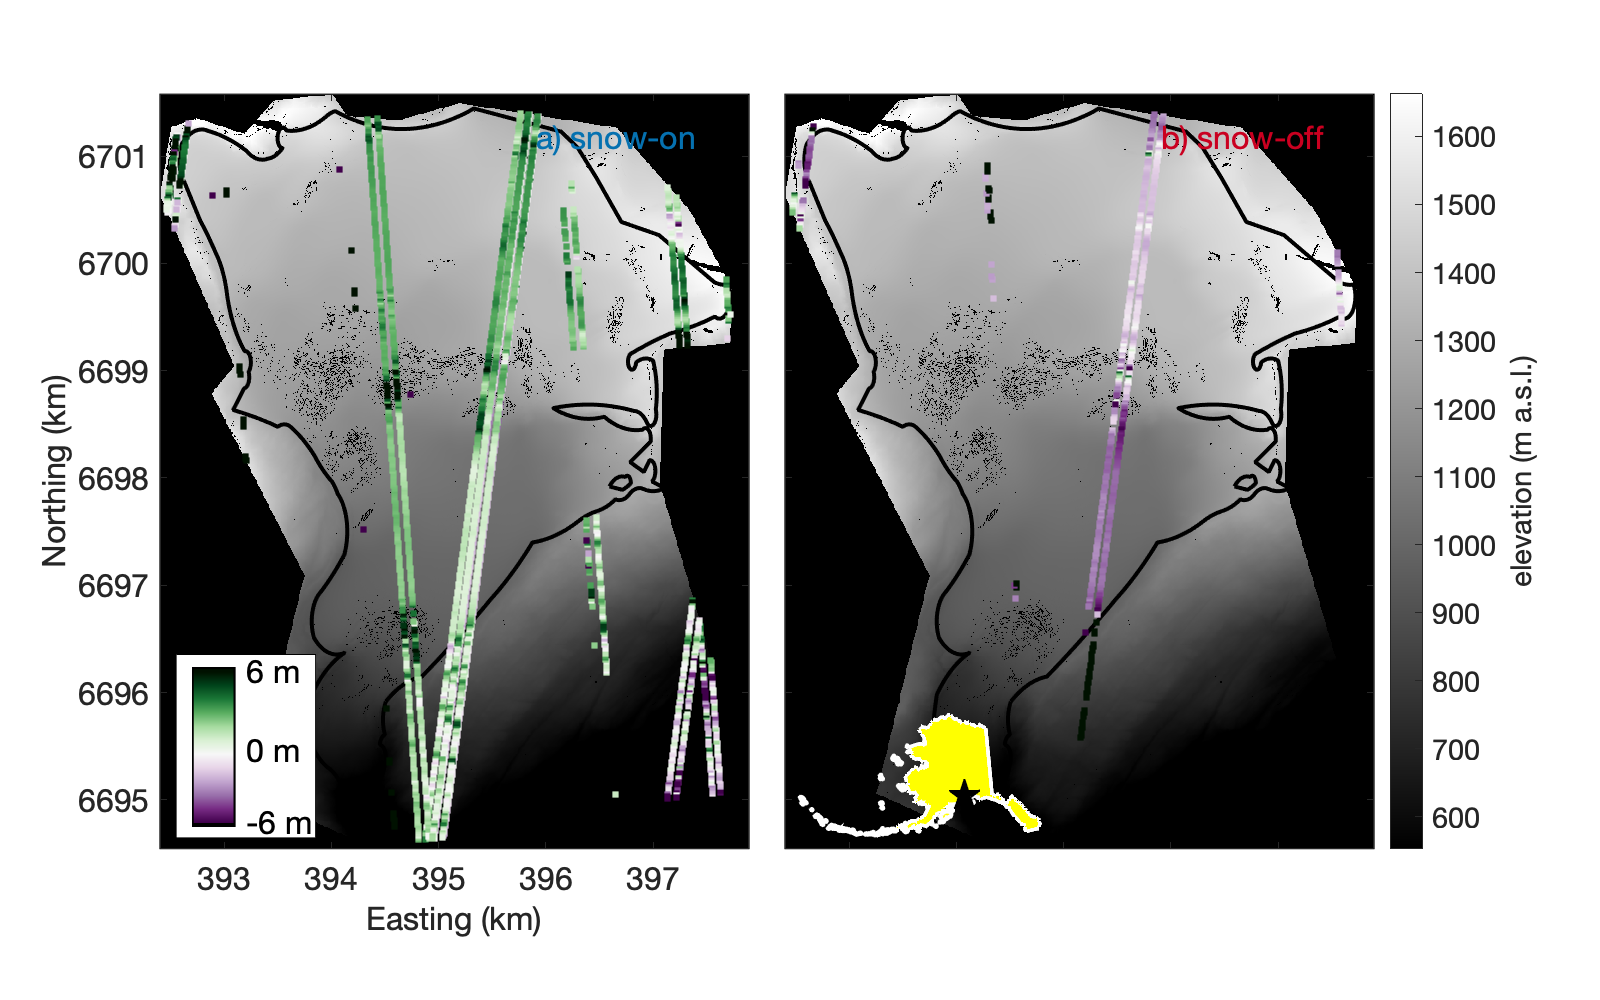

%create a reference map
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%set limits of elevation residuals for color stretching
max_residual = 6; %ceil(max(Tin.('differences'))) %swap this in if you want to stretch colors over the full range of residuals

%mask-out the portion of the DEM outside of the catchment
Z(2).z(Z(2).z<0) = NaN;
[DEMxgrid,DEMygrid] = meshgrid(Z(2).x,Z(2).y);
[in,~] = inpolygon(DEMxgrid,DEMygrid,catchment.X(1:end-1),catchment.Y(1:end-1));
Z(2).z(in==0) = NaN;
xmax = max(max(DEMxgrid(in==1))); xmin = min(min(DEMxgrid(in==1))); ymax = max(max(DEMygrid(in==1))); ymin = min(min(DEMygrid(in==1)));
clear in;

%set elevation range for maps
elev_lims = [min(min(Tin.ReferenceElevation)) max(max(Tin.ReferenceElevation))];
elevmap = Z(2).z; elevmap(elevmap<min(elev_lims)) = min(elev_lims)+1;

%create a more detailed colorramp for the elevation residuals than the
%11-color import from colorbrewer
resids_cmap = cblind_colors;
while size(resids_cmap,1) < 500
    for j = 1:2*size(resids_cmap,1)
        if mod(j,2) ~= 0
            new_cmap(j,:) = resids_cmap(ceil(j/2),:);
        else
            if j < 2*size(resids_cmap,1)
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2):ceil(j/2)+1,:));
            else
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2)-1:ceil(j/2),:));
            end
        end
    end
    resids_cmap = new_cmap; clear new_cmap;
    resids_cmap(resids_cmap<0) = 0;
%     disp(size(resids_cmap,1))
end

%create color matrices for each season
multiplier = size(resids_cmap,1)/(2*max_residual); %solve for a multiplier to map data values onto a colorramp
%snow-on season
acc_diff = T.differences(T.season == 1 | T.season == 2 | T.season == 4); acc_x = T.Easting(T.season == 1 | T.season == 2 | T.season == 4); acc_y = T.Northing(T.season == 1 | T.season == 2 | T.season == 4);
acc_x(isnan(acc_diff)) = []; acc_y(isnan(acc_diff)) = []; acc_diff(isnan(acc_diff)) = [];
acc_colormat = ones(length(acc_diff),3);
for j = 1:length(acc_diff)
    cref = round((acc_diff(j)+max_residual)*multiplier);
    if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
    acc_colormat(j,:) = resids_cmap(cref,:);
end
acc_colormat(acc_colormat<0) = 0;
%snow-off season
abl_diff = T.differences(T.season == 3); abl_x = T.Easting(T.season == 3); abl_y = T.Northing(T.season == 3);
abl_x(isnan(abl_diff)) = []; abl_y(isnan(abl_diff)) = []; abl_diff(isnan(abl_diff)) = [];
abl_colormat = ones(length(abl_diff),3);
for j = 1:length(abl_diff)
    cref = round((abl_diff(j)+max_residual)*multiplier);
    if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
    abl_colormat(j,:) = resids_cmap(cref,:);
end
abl_colormat(abl_colormat<0) = 0;

%create the map
WGmap = figure; set(gcf,'position',[0 0 800 500],'DefaultTextFontSize', 16);
asl_cmap = colormap(gray(5001));
for i = 1:2
    subplot(1,2,i)
    imagesc(Z(2).x,Z(2).y,elevmap); axis xy equal; % colormap gray; 
    colormap(gca,asl_cmap); set(gca,'clim',elev_lims); hold on; drawnow;
    set(gca,'fontsize',16,'xlim',[xmin xmax],'ylim',[ymin ymax]);
    xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
    subpos = get(gca,'position');
    %plot the shapefile outline
    plot([S.X S.X(1)],[S.Y S.Y(1)],'-k','linewidth',2); hold on;
    
    %set axis labels
    if i == 1
        set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
    else
        set(gca,'xticklabels',[],'yticklabels',[]);
    end
    if i == 2
        cbar = colorbar; cbar.Label.String = 'elevation (m a.s.l.)';
        set(cbar,'location','eastoutside','orientation','vertical')
    elseif i == 1
        xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
    end
    
    %add data & labels
    if i == 1
        scatter(acc_x,acc_y,16,acc_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;

        %add colorramp
        rectangle('Position',[xmin+150 ymin+100 1300 2*size(resids_cmap,1)+300],'facecolor','w'); %colorramp legend background
        rectangle('Position',[xmin+300 ymin+2*1+200 400 2*size(resids_cmap,1)+80],'facecolor','k');
        for j = 1:length(resids_cmap)
            plot(squeeze([xmin+315; xmin+685]),squeeze([ymin+2*j+250; ymin+2*j+250]),'color',resids_cmap(j,:),'linewidth',1.5); hold on;
        end
        text(xmin+800,ymin+2*size(resids_cmap,1)+250,[num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmin+800,ymin+0.95*size(resids_cmap,1)+250,'0 m','color','k','fontsize',16);
        text(xmin+800,ymin+250,['-',num2str(max_residual),' m'],'color','k','fontsize',16);
        text(xmin+3750,ymax-300,'a) snow-on','color',seas_cmap(1,:),'fontsize',16);
        
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.03 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    elseif i == 2
        scatter(abl_x,abl_y,16,abl_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
        text(xmin+3750,ymax-300,'b) snow-off','color',seas_cmap(2,:),'fontsize',16);
        set(gca,'yticklabel',[]);
        %enlarge subplot
        set(gca,'position',[subpos(1)-0.08 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
    end
    drawnow; hold on;
end

%overlay a state map in an open space
% axes_pos = get(map_ax,'position');
inset_ax = axes('Position', [0.50, 0.15, 0.15, 0.15]);
nanrefs = find(isnan(state.X));
for i = 1:length(nanrefs)
    if i == 1
        fill([state.X(1:nanrefs(i)-1) state.X(1)],[state.Y(1:nanrefs(i)-1) state.Y(1)],[1 1 1],'facecolor',[1 1 0],'edgecolor','w','linewidth',2); hold on;
        fill([state.X(1:nanrefs(i)-1) state.X(1)],[state.Y(1:nanrefs(i)-1) state.Y(1)],[1 1 1],'facecolor','none','edgecolor','w','linewidth',2); hold on;
    else
        fill([state.X(nanrefs(i-1)+1:nanrefs(i)-1) state.X(nanrefs(i-1)+1)],[state.Y(nanrefs(i-1)+1:nanrefs(i)-1) state.Y(nanrefs(i-1)+1)],[1 1 1],'edgecolor','w','facecolor',[1 1 0],'linewidth',2); hold on;
        fill([state.X(nanrefs(i-1)+1:nanrefs(i)-1) state.X(nanrefs(i-1)+1)],[state.Y(nanrefs(i-1)+1:nanrefs(i)-1) state.Y(nanrefs(i-1)+1)],[1 1 1],'edgecolor','w','facecolor','none','linewidth',2); hold on;
    end
end
plot(inset_ax,nanmean(S.X),nanmean(S.Y),'pk','linewidth',1,'markersize',16,'markerfacecolor','k'); axis xy equal;
set(inset_ax,'xlim',[min(state.X) max(state.X)],'ylim',[min(state.Y) max(state.Y)],'XTick',[],'YTick',[],'color','none','XColor','none','YColor','none');

%save!
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);
saveas(gcf,[abbrev,'_ICESat2residuals-map.eps'],'epsc');